## Final Evaluation Setup

clear;
clc;
close all;

% ---------------------------------------------------------
% Locate project folder
% ---------------------------------------------------------

scriptPath = matlab.desktop.editor.getActiveFilename;
codeFolder = fileparts(scriptPath);
projectRoot = fileparts(codeFolder);

dataFolder = fullfile(projectRoot, 'data', 'flute');
audioFolder = fullfile(projectRoot, 'audio_output');
resultsFolder = fullfile(projectRoot, 'results');

% Create results folder if necessary
if ~exist(resultsFolder, 'dir')
    mkdir(resultsFolder);
end


%% Target Notes

notes = {'C4', 'E4', 'A4'};

f0Values = [260.79, 329.73, 442.25];


%% Reference Audio Files

referenceFiles = {
    fullfile(dataFolder, 'Flute.nonvib.ff.C4.stereo.aif')
    fullfile(dataFolder, 'Flute.nonvib.ff.E4.stereo.aif')
    fullfile(dataFolder, 'Flute.nonvib.ff.A4.stereo.aif')
};


%% Final Additive Synthesis Files

additiveFiles = {
    fullfile(audioFolder, 'Flute_C4_TimeVarying_Additive.wav')
    fullfile(audioFolder, 'Flute_E4_TimeVarying_Additive.wav')
    fullfile(audioFolder, 'Flute_A4_TimeVarying_Additive.wav')
};


%% Final FM Synthesis Files

fmFiles = {
    fullfile(audioFolder, 'Flute_C4_MultiStart_FM.wav')
    fullfile(audioFolder, 'Flute_E4_MultiStart_FM.wav')
    fullfile(audioFolder, 'Flute_A4_MultiStart_FM.wav')
};



fprintf('Final Evaluation File Check\n');

Final Evaluation File Check




allFilesAvailable = true;

for i = 1:length(notes)

    fprintf('\n%s:\n', notes{i});

    % Reference
    if isfile(referenceFiles{i})
        fprintf('Reference audio: FOUND\n');
    else
        fprintf('Reference audio: MISSING\n');
        allFilesAvailable = false;
    end

    % Additive
    if isfile(additiveFiles{i})
        fprintf('Additive audio:  FOUND\n');
    else
        fprintf('Additive audio:  MISSING\n');
        allFilesAvailable = false;
    end

    % FM
    if isfile(fmFiles{i})
        fprintf('FM audio:        FOUND\n');
    else
        fprintf('FM audio:        MISSING\n');
        allFilesAvailable = false;
    end

end


C4:


Reference audio: FOUND


Additive audio:  FOUND


FM audio:        FOUND



E4:


Reference audio: FOUND


Additive audio:  FOUND


FM audio:        FOUND



A4:


Reference audio: FOUND


Additive audio:  FOUND


FM audio:        FOUND




%% Final Check



if allFilesAvailable

    fprintf('All required audio files are available.\n');
    fprintf('Ready for final quantitative evaluation.\n');

else

    fprintf('Some required files are missing.\n');
    fprintf('Check the filenames shown above.\n');

end

All required audio files are available.


Ready for final quantitative evaluation.


###  Log-Spectral Distance Evaluation


% ---------------------------------------------------------
% Evaluation parameters
% ---------------------------------------------------------

windowLength = 2048;
overlapLength = 1536;
nfft = 4096;

maxEvalFrequency = 5000;

numNotes = length(notes);

additiveLSD = zeros(numNotes,1);
fmLSD = zeros(numNotes,1);


%% Calculate LSD for C4, E4 and A4

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = audioread(referenceFiles{i});
    [xAdd, fsAdd] = audioread(additiveFiles{i});
    [xFM, fsFM] = audioread(fmFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise signals
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % STFT
    % -----------------------------------------------------

    [Sref, F, ~] = spectrogram( ...
        xRef, ...
        hann(windowLength), ...
        overlapLength, ...
        nfft, ...
        fs);

    [Sadd, ~, ~] = spectrogram( ...
        xAdd, ...
        hann(windowLength), ...
        overlapLength, ...
        nfft, ...
        fs);

    [Sfm, ~, ~] = spectrogram( ...
        xFM, ...
        hann(windowLength), ...
        overlapLength, ...
        nfft, ...
        fs);


    % -----------------------------------------------------
    % Restrict evaluation to 0-5 kHz
    % -----------------------------------------------------

    freqMask = F <= maxEvalFrequency;

    refMag = abs(Sref(freqMask,:));
    addMag = abs(Sadd(freqMask,:));
    fmMag  = abs(Sfm(freqMask,:));


    % -----------------------------------------------------
    % Convert to log magnitude
    % -----------------------------------------------------

    epsilon = 1e-8;

    refLog = 20 * log10(refMag + epsilon);
    addLog = 20 * log10(addMag + epsilon);
    fmLog  = 20 * log10(fmMag  + epsilon);


    % -----------------------------------------------------
    % Frame-wise LSD
    % -----------------------------------------------------

    additiveFrameLSD = sqrt( ...
        mean( ...
        (refLog - addLog).^2, ...
        1));

    fmFrameLSD = sqrt( ...
        mean( ...
        (refLog - fmLog).^2, ...
        1));


    % -----------------------------------------------------
    % Mean LSD for each note
    % -----------------------------------------------------

    additiveLSD(i) = mean(additiveFrameLSD);
    fmLSD(i) = mean(fmFrameLSD);

end


%% Results Table

LSDTable = table( ...
    notes', ...
    additiveLSD, ...
    fmLSD, ...
    'VariableNames', ...
    {'Note', ...
     'Additive_LSD_dB', ...
     'FM_LSD_dB'});

LSDTable

LSDTable = 3×3 table
     Note     Additive_LSD_dB    FM_LSD_dB
    ______    _______________    _________

    {'C4'}        42.081          23.157  
    {'E4'}        36.227          25.412  
    {'A4'}        27.133          25.216  

	使用 Copilot 获取洞察




%% Mean Results

meanAdditiveLSD = mean(additiveLSD);
meanFMLSD = mean(fmLSD);

LSDMeanTable = table( ...
    meanAdditiveLSD, ...
    meanFMLSD, ...
    'VariableNames', ...
    {'Mean_Additive_LSD_dB', ...
     'Mean_FM_LSD_dB'});

LSDMeanTable

LSDMeanTable = 1×2 table
    Mean_Additive_LSD_dB    Mean_FM_LSD_dB
    ____________________    ______________

           35.147               24.595    

	使用 Copilot 获取洞察


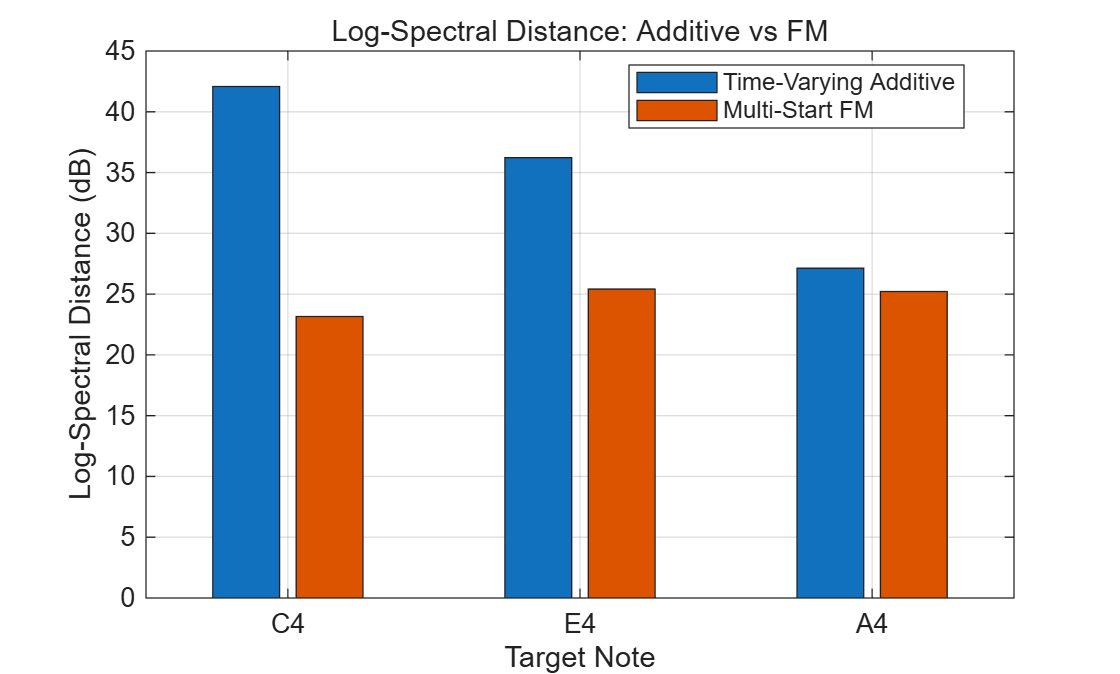



%% LSD Comparison Figure

figure;

bar([additiveLSD, fmLSD]);

xlabel('Target Note');
ylabel('Log-Spectral Distance (dB)');

title('Log-Spectral Distance: Additive vs FM');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Final_LSD_Results.csv');

writetable( ...
    LSDTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'Final_LSD_Mean_Results.csv');

writetable( ...
    LSDMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Final_LSD_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Multi-Resolution STFT Error Evaluation


% ---------------------------------------------------------
% Three STFT resolutions
% Short / medium / long windows
% ---------------------------------------------------------

windowLengths = [512, 2048, 8192];
nfftValues    = [1024, 4096, 16384];

maxEvalFrequency = 5000;

numNotes = length(notes);
numResolutions = length(windowLengths);

% Store errors for each resolution
additiveMRSTFT = zeros(numNotes, numResolutions);
fmMRSTFT       = zeros(numNotes, numResolutions);


%% Calculate Multi-Resolution STFT Error

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = audioread(referenceFiles{i});
    [xAdd, fsAdd] = audioread(additiveFiles{i});
    [xFM, fsFM]   = audioread(fmFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise signals
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % Evaluate three STFT resolutions
    % -----------------------------------------------------

    for r = 1:numResolutions

        windowLength = windowLengths(r);

        % 75% overlap
        overlapLength = round(0.75 * windowLength);

        nfft = nfftValues(r);


        % Reference STFT
        [Sref, F, ~] = spectrogram( ...
            xRef, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);


        % Additive STFT
        [Sadd, ~, ~] = spectrogram( ...
            xAdd, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);


        % FM STFT
        [Sfm, ~, ~] = spectrogram( ...
            xFM, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);


        % -------------------------------------------------
        % Restrict evaluation to 0-5 kHz
        % -------------------------------------------------

        freqMask = F <= maxEvalFrequency;

        refMag = abs(Sref(freqMask,:));
        addMag = abs(Sadd(freqMask,:));
        fmMag  = abs(Sfm(freqMask,:));


        % -------------------------------------------------
        % Normalised spectral magnitude error
        % -------------------------------------------------

        epsilon = 1e-12;

        referenceEnergy = ...
            norm(refMag, 'fro') + epsilon;

        additiveMRSTFT(i,r) = ...
            norm(refMag - addMag, 'fro') / ...
            referenceEnergy;

        fmMRSTFT(i,r) = ...
            norm(refMag - fmMag, 'fro') / ...
            referenceEnergy;

    end

end


%% Combined Multi-Resolution Error

% Mean across short, medium and long resolutions

additiveMRMean = mean(additiveMRSTFT, 2);
fmMRMean       = mean(fmMRSTFT, 2);


%% Detailed Results Table

MRSTFTTable = table( ...
    notes', ...
    additiveMRSTFT(:,1), ...
    additiveMRSTFT(:,2), ...
    additiveMRSTFT(:,3), ...
    additiveMRMean, ...
    fmMRSTFT(:,1), ...
    fmMRSTFT(:,2), ...
    fmMRSTFT(:,3), ...
    fmMRMean, ...
    'VariableNames', ...
    { ...
    'Note', ...
    'Additive_Short', ...
    'Additive_Medium', ...
    'Additive_Long', ...
    'Additive_MR_Mean', ...
    'FM_Short', ...
    'FM_Medium', ...
    'FM_Long', ...
    'FM_MR_Mean' ...
    });

MRSTFTTable

MRSTFTTable = 3×9 table
     Note     Additive_Short    Additive_Medium    Additive_Long    Additive_MR_Mean    FM_Short    FM_Medium    FM_Long    FM_MR_Mean
    ______    ______________    _______________    _____________    ________________    ________    _________    _______    __________

    {'C4'}        0.16245           0.16137           0.20532           0.17638          1.3877      1.6608      1.7786        1.609  
    {'E4'}       0.058469           0.08241           0.22032            0.1204          1.5581      1.8282      1.8661       1.7508  
    {'A4'}        0.04633           0.15004           0.45973            0.2187          1.4248      1.6676      1.6882       1.5935  

	使用 Copilot 获取洞察




%% Overall Mean Results

meanAdditiveMRSTFT = mean(additiveMRMean);
meanFMMRSTFT       = mean(fmMRMean);

MRSTFTMeanTable = table( ...
    meanAdditiveMRSTFT, ...
    meanFMMRSTFT, ...
    'VariableNames', ...
    { ...
    'Mean_Additive_MRSTFT_Error', ...
    'Mean_FM_MRSTFT_Error' ...
    });

MRSTFTMeanTable

MRSTFTMeanTable = 1×2 table
    Mean_Additive_MRSTFT_Error    Mean_FM_MRSTFT_Error
    __________________________    ____________________

             0.17183                     1.6511       

	使用 Copilot 获取洞察


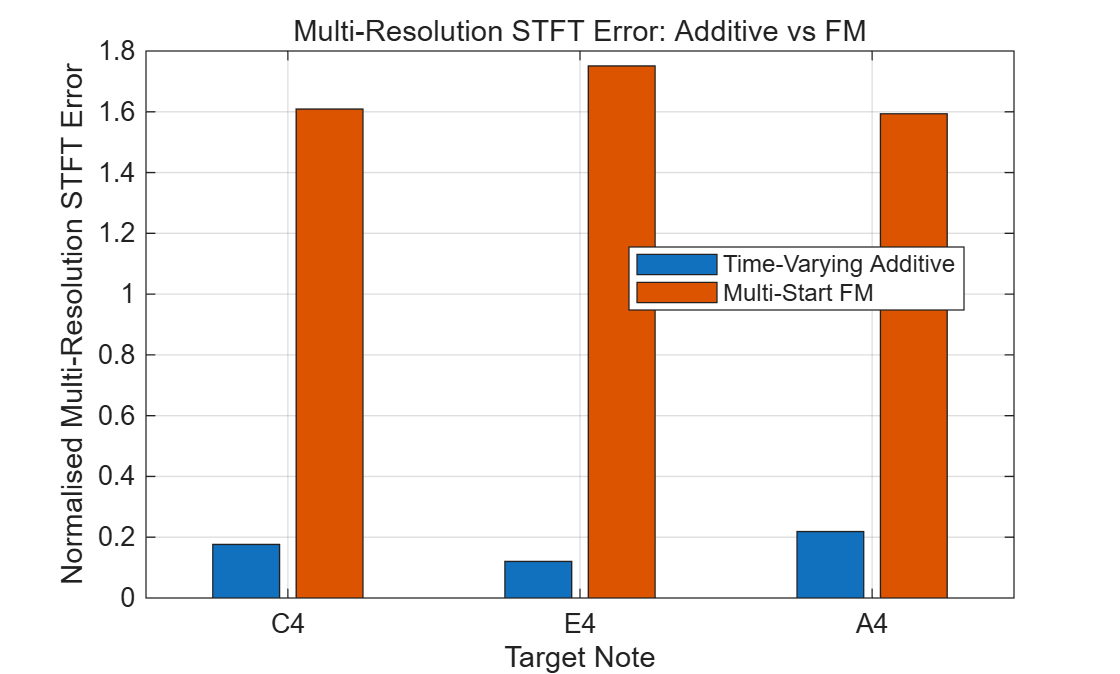



%% Multi-Resolution STFT Comparison Figure

figure;

bar([additiveMRMean, fmMRMean]);

xlabel('Target Note');
ylabel('Normalised Multi-Resolution STFT Error');

title('Multi-Resolution STFT Error: Additive vs FM');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Final_MRSTFT_Results.csv');

writetable( ...
    MRSTFTTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'Final_MRSTFT_Mean_Results.csv');

writetable( ...
    MRSTFTMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Final_MRSTFT_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Harmonic Amplitude Error Evaluation


% ---------------------------------------------------------
% Evaluation settings
% ---------------------------------------------------------

numHarmonics = 10;
harmonicSearchRangeHz = 20;

numNotes = length(notes);

referenceHarmonics = zeros(numNotes, numHarmonics);
additiveHarmonics  = zeros(numNotes, numHarmonics);
fmHarmonics        = zeros(numNotes, numHarmonics);

additiveHarmonicError = zeros(numNotes,1);
fmHarmonicError       = zeros(numNotes,1);


%% Calculate Harmonic Amplitude Error

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = audioread(referenceFiles{i});
    [xAdd, fsAdd] = audioread(additiveFiles{i});
    [xFM, fsFM]   = audioread(fmFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise waveform amplitude
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % FFT with zero padding
    % -----------------------------------------------------

    signalLength = length(xRef);

    nfftHarmonic = ...
        4 * 2^nextpow2(signalLength);

    analysisWindow = hann(signalLength);


    Xref = fft( ...
        xRef .* analysisWindow, ...
        nfftHarmonic);

    Xadd = fft( ...
        xAdd .* analysisWindow, ...
        nfftHarmonic);

    Xfm = fft( ...
        xFM .* analysisWindow, ...
        nfftHarmonic);


    % One-sided spectra

    halfLength = floor(nfftHarmonic/2) + 1;

    refSpectrum = abs(Xref(1:halfLength));
    addSpectrum = abs(Xadd(1:halfLength));
    fmSpectrum  = abs(Xfm(1:halfLength));

    frequencyAxis = ...
        (0:halfLength-1)' * ...
        fs / nfftHarmonic;


    % -----------------------------------------------------
    % Extract harmonic peak amplitudes
    % -----------------------------------------------------

    f0 = f0Values(i);

    for h = 1:numHarmonics

        targetFrequency = h * f0;

        searchMask = ...
            frequencyAxis >= ...
            (targetFrequency - harmonicSearchRangeHz) & ...
            frequencyAxis <= ...
            (targetFrequency + harmonicSearchRangeHz);


        referenceHarmonics(i,h) = ...
            max(refSpectrum(searchMask));

        additiveHarmonics(i,h) = ...
            max(addSpectrum(searchMask));

        fmHarmonics(i,h) = ...
            max(fmSpectrum(searchMask));

    end


    % -----------------------------------------------------
    % Convert to relative harmonic distributions
    % -----------------------------------------------------

    refHarmonicVector = referenceHarmonics(i,:);
    addHarmonicVector = additiveHarmonics(i,:);
    fmHarmonicVector  = fmHarmonics(i,:);


    if sum(refHarmonicVector) > 0
        refHarmonicVector = ...
            refHarmonicVector / ...
            sum(refHarmonicVector);
    end

    if sum(addHarmonicVector) > 0
        addHarmonicVector = ...
            addHarmonicVector / ...
            sum(addHarmonicVector);
    end

    if sum(fmHarmonicVector) > 0
        fmHarmonicVector = ...
            fmHarmonicVector / ...
            sum(fmHarmonicVector);
    end


    % Save normalised distributions

    referenceHarmonics(i,:) = refHarmonicVector;
    additiveHarmonics(i,:)  = addHarmonicVector;
    fmHarmonics(i,:)        = fmHarmonicVector;


    % -----------------------------------------------------
    % Normalised RMSE of harmonic amplitudes
    % -----------------------------------------------------

    additiveHarmonicError(i) = sqrt( ...
        mean( ...
        (refHarmonicVector - ...
         addHarmonicVector).^2));

    fmHarmonicError(i) = sqrt( ...
        mean( ...
        (refHarmonicVector - ...
         fmHarmonicVector).^2));

end


%% Harmonic Error Results Table

HarmonicErrorTable = table( ...
    notes', ...
    additiveHarmonicError, ...
    fmHarmonicError, ...
    'VariableNames', ...
    { ...
    'Note', ...
    'Additive_Harmonic_Error', ...
    'FM_Harmonic_Error' ...
    });

HarmonicErrorTable

HarmonicErrorTable = 3×3 table
     Note     Additive_Harmonic_Error    FM_Harmonic_Error
    ______    _______________________    _________________

    {'C4'}           0.010463                 0.28351     
    {'E4'}           0.029305                 0.21921     
    {'A4'}           0.017024                 0.27437     

	使用 Copilot 获取洞察




%% Mean Harmonic Error

meanAdditiveHarmonicError = ...
    mean(additiveHarmonicError);

meanFMHarmonicError = ...
    mean(fmHarmonicError);

HarmonicMeanTable = table( ...
    meanAdditiveHarmonicError, ...
    meanFMHarmonicError, ...
    'VariableNames', ...
    { ...
    'Mean_Additive_Harmonic_Error', ...
    'Mean_FM_Harmonic_Error' ...
    });

HarmonicMeanTable

HarmonicMeanTable = 1×2 table
    Mean_Additive_Harmonic_Error    Mean_FM_Harmonic_Error
    ____________________________    ______________________

              0.018931                     0.25903        

	使用 Copilot 获取洞察


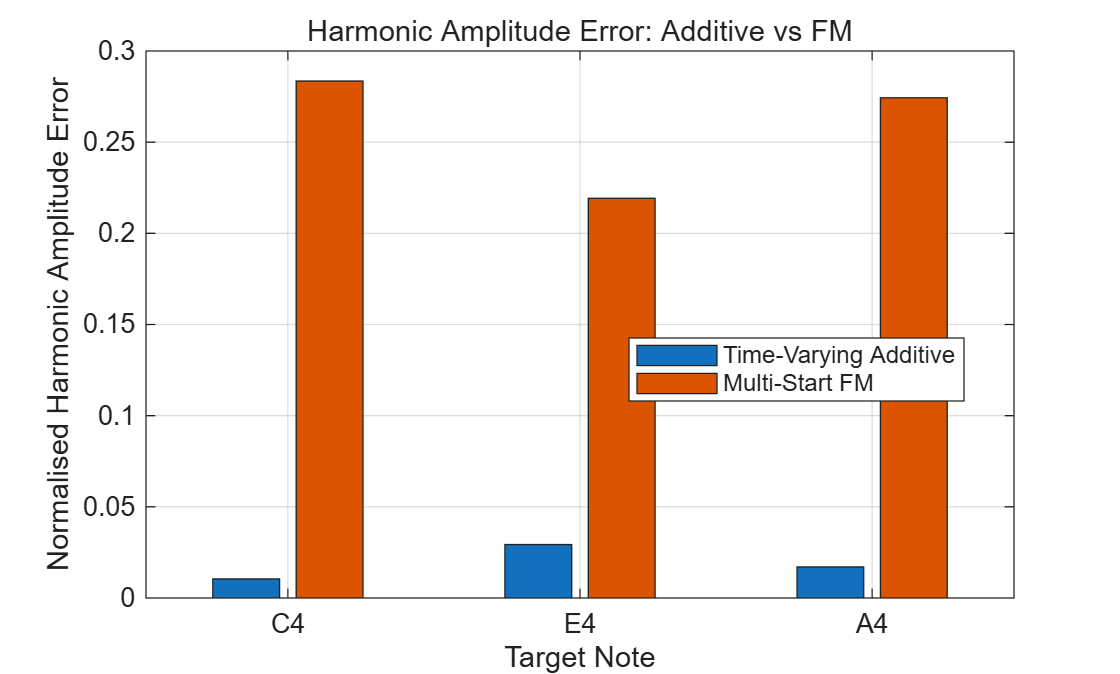



%% Harmonic Error Comparison Figure

figure;

bar([ ...
    additiveHarmonicError, ...
    fmHarmonicError]);

xlabel('Target Note');

ylabel( ...
    'Normalised Harmonic Amplitude Error');

title( ...
    'Harmonic Amplitude Error: Additive vs FM');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Final_Harmonic_Error_Results.csv');

writetable( ...
    HarmonicErrorTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'Final_Harmonic_Error_Mean_Results.csv');

writetable( ...
    HarmonicMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Final_Harmonic_Error_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Temporal-Envelope Error Evaluation


% ---------------------------------------------------------
% Evaluation settings
% ---------------------------------------------------------

envelopeWindowSeconds = 0.02;

numNotes = length(notes);

additiveEnvelopeError = zeros(numNotes,1);
fmEnvelopeError       = zeros(numNotes,1);


%% Calculate Temporal-Envelope Error

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = audioread(referenceFiles{i});
    [xAdd, fsAdd] = audioread(additiveFiles{i});
    [xFM, fsFM]   = audioread(fmFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise waveform amplitudes
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % Extract RMS temporal envelopes
    % -----------------------------------------------------

    envelopeWindow = ...
        round(envelopeWindowSeconds * fs);

    refEnvelope = sqrt( ...
        movmean(xRef.^2, envelopeWindow));

    addEnvelope = sqrt( ...
        movmean(xAdd.^2, envelopeWindow));

    fmEnvelope = sqrt( ...
        movmean(xFM.^2, envelopeWindow));


    % -----------------------------------------------------
    % Normalise envelopes
    % -----------------------------------------------------

    if max(refEnvelope) > 0
        refEnvelope = ...
            refEnvelope / max(refEnvelope);
    end

    if max(addEnvelope) > 0
        addEnvelope = ...
            addEnvelope / max(addEnvelope);
    end

    if max(fmEnvelope) > 0
        fmEnvelope = ...
            fmEnvelope / max(fmEnvelope);
    end


    % -----------------------------------------------------
    % Envelope RMSE
    % -----------------------------------------------------

    additiveEnvelopeError(i) = sqrt( ...
        mean( ...
        (refEnvelope - addEnvelope).^2));

    fmEnvelopeError(i) = sqrt( ...
        mean( ...
        (refEnvelope - fmEnvelope).^2));

end


%% Temporal-Envelope Results Table

EnvelopeErrorTable = table( ...
    notes', ...
    additiveEnvelopeError, ...
    fmEnvelopeError, ...
    'VariableNames', ...
    { ...
    'Note', ...
    'Additive_Envelope_Error', ...
    'FM_Envelope_Error' ...
    });

EnvelopeErrorTable

EnvelopeErrorTable = 3×3 table
     Note     Additive_Envelope_Error    FM_Envelope_Error
    ______    _______________________    _________________

    {'C4'}           0.029439                 0.014879    
    {'E4'}           0.018582                 0.018455    
    {'A4'}           0.012416                0.0061754    

	使用 Copilot 获取洞察




%% Mean Temporal-Envelope Error

meanAdditiveEnvelopeError = ...
    mean(additiveEnvelopeError);

meanFMEnvelopeError = ...
    mean(fmEnvelopeError);

EnvelopeMeanTable = table( ...
    meanAdditiveEnvelopeError, ...
    meanFMEnvelopeError, ...
    'VariableNames', ...
    { ...
    'Mean_Additive_Envelope_Error', ...
    'Mean_FM_Envelope_Error' ...
    });

EnvelopeMeanTable

EnvelopeMeanTable = 1×2 table
    Mean_Additive_Envelope_Error    Mean_FM_Envelope_Error
    ____________________________    ______________________

              0.020146                     0.01317        

	使用 Copilot 获取洞察


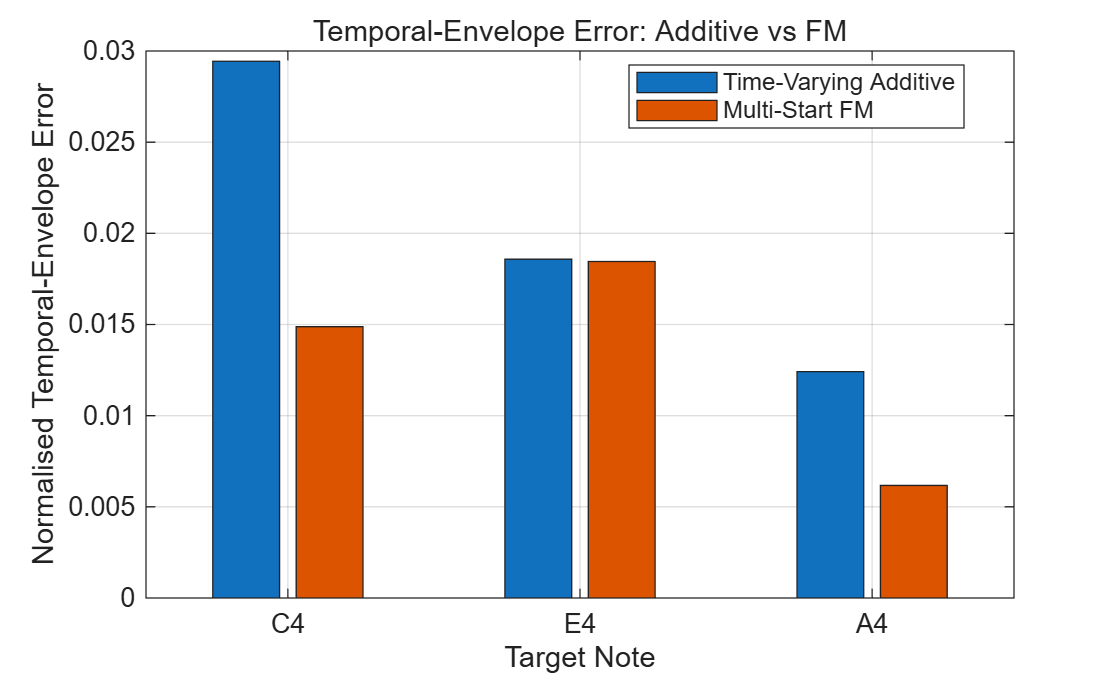



%% Temporal-Envelope Error Comparison Figure

figure;

bar([ ...
    additiveEnvelopeError, ...
    fmEnvelopeError]);

xlabel('Target Note');

ylabel('Normalised Temporal-Envelope Error');

title( ...
    'Temporal-Envelope Error: Additive vs FM');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Final_Envelope_Error_Results.csv');

writetable( ...
    EnvelopeErrorTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'Final_Envelope_Error_Mean_Results.csv');

writetable( ...
    EnvelopeMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Final_Envelope_Error_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Leave-One-Pitch-Out Additive Synthesis


% ---------------------------------------------------------
% Settings
% ---------------------------------------------------------

numHarmonicsLOPO = 10;

harmonicSearchRangeHz = 20;

envelopeWindowSeconds = 0.02;

normalisedEnvelopeLength = 200;


% ---------------------------------------------------------
% Leave-one-pitch-out folds
%
% Fold 1: C4 + E4 -> A4
% Fold 2: C4 + A4 -> E4
% Fold 3: E4 + A4 -> C4
% ---------------------------------------------------------

trainingPairs = [
    1 2
    1 3
    2 3
];

heldOutIndices = [
    3
    2
    1
];

numFolds = size(trainingPairs,1);


% ---------------------------------------------------------
% Storage
% ---------------------------------------------------------

sharedHarmonicProfiles = ...
    zeros(numFolds, numHarmonicsLOPO);

sharedEnvelopeProfiles = ...
    zeros(numFolds, normalisedEnvelopeLength);

lopoAdditiveFiles = cell(numFolds,1);


%% Fit Shared Additive Timbre and Predict Held-Out Pitch

for fold = 1:numFolds

    trainIndices = trainingPairs(fold,:);
    testIndex = heldOutIndices(fold);


    % -----------------------------------------------------
    % Storage for the two training notes
    % -----------------------------------------------------

    trainingHarmonics = ...
        zeros(2, numHarmonicsLOPO);

    trainingEnvelopes = ...
        zeros(2, normalisedEnvelopeLength);


    % -----------------------------------------------------
    % Analyse both training notes
    % -----------------------------------------------------

    for j = 1:2

        trainIndex = trainIndices(j);


        % -------------------------------------------------
        % Load training reference
        % -------------------------------------------------

        [xTrain, fsTrain] = ...
            audioread(referenceFiles{trainIndex});


        % -------------------------------------------------
        % Convert to mono
        % -------------------------------------------------

        if size(xTrain,2) == 2
            xTrain = mean(xTrain,2);
        end


        % -------------------------------------------------
        % Normalise waveform
        % -------------------------------------------------

        if max(abs(xTrain)) > 0
            xTrain = ...
                xTrain / max(abs(xTrain));
        end


        % -------------------------------------------------
        % Extract steady-state region
        %
        % Use approximately the middle 60% of the note
        % so attack and release do not dominate the
        % harmonic timbre estimate.
        % -------------------------------------------------

        signalLength = length(xTrain);

        steadyStart = ...
            max(1, round(0.20 * signalLength));

        steadyEnd = ...
            min(signalLength, ...
            round(0.80 * signalLength));

        xSteady = ...
            xTrain(steadyStart:steadyEnd);


        % -------------------------------------------------
        % FFT for harmonic extraction
        % -------------------------------------------------

        steadyLength = length(xSteady);

        nfftLOPO = ...
            4 * 2^nextpow2(steadyLength);

        analysisWindow = hann(steadyLength);

        Xtrain = fft( ...
            xSteady .* analysisWindow, ...
            nfftLOPO);

        halfLength = ...
            floor(nfftLOPO/2) + 1;

        trainSpectrum = ...
            abs(Xtrain(1:halfLength));

        frequencyAxis = ...
            (0:halfLength-1)' * ...
            fsTrain / nfftLOPO;


        % -------------------------------------------------
        % Extract first 10 harmonic amplitudes
        % -------------------------------------------------

        f0Train = ...
            f0Values(trainIndex);

        harmonicVector = ...
            zeros(1, numHarmonicsLOPO);


        for h = 1:numHarmonicsLOPO

            targetFrequency = ...
                h * f0Train;

            searchMask = ...
                frequencyAxis >= ...
                (targetFrequency - ...
                 harmonicSearchRangeHz) & ...
                frequencyAxis <= ...
                (targetFrequency + ...
                 harmonicSearchRangeHz);


            if any(searchMask)

                harmonicVector(h) = ...
                    max(trainSpectrum(searchMask));

            end

        end


        % -------------------------------------------------
        % Convert to relative harmonic amplitudes
        % -------------------------------------------------

        if sum(harmonicVector) > 0

            harmonicVector = ...
                harmonicVector / ...
                sum(harmonicVector);

        end

        trainingHarmonics(j,:) = ...
            harmonicVector;


        % -------------------------------------------------
        % Extract RMS amplitude envelope
        % -------------------------------------------------

        envelopeWindow = ...
            max(1, ...
            round( ...
            envelopeWindowSeconds * ...
            fsTrain));

        amplitudeEnvelope = sqrt( ...
            movmean( ...
            xTrain.^2, ...
            envelopeWindow));


        % -------------------------------------------------
        % Normalise envelope
        % -------------------------------------------------

        if max(amplitudeEnvelope) > 0

            amplitudeEnvelope = ...
                amplitudeEnvelope / ...
                max(amplitudeEnvelope);

        end


        % -------------------------------------------------
        % Convert envelope to normalised time
        %
        % This removes the specific duration of the
        % training note and preserves only its shape.
        % -------------------------------------------------

        originalTime = ...
            linspace( ...
            0, ...
            1, ...
            length(amplitudeEnvelope));

        normalisedTime = ...
            linspace( ...
            0, ...
            1, ...
            normalisedEnvelopeLength);


        trainingEnvelopes(j,:) = ...
            interp1( ...
            originalTime, ...
            amplitudeEnvelope, ...
            normalisedTime, ...
            'linear');

    end


    % -----------------------------------------------------
    % Shared harmonic timbre profile
    % -----------------------------------------------------

    sharedHarmonicProfile = ...
        mean(trainingHarmonics,1);

    if sum(sharedHarmonicProfile) > 0

        sharedHarmonicProfile = ...
            sharedHarmonicProfile / ...
            sum(sharedHarmonicProfile);

    end


    sharedHarmonicProfiles(fold,:) = ...
        sharedHarmonicProfile;


    % -----------------------------------------------------
    % Shared temporal-envelope shape
    % -----------------------------------------------------

    sharedEnvelopeProfile = ...
        mean(trainingEnvelopes,1);

    if max(sharedEnvelopeProfile) > 0

        sharedEnvelopeProfile = ...
            sharedEnvelopeProfile / ...
            max(sharedEnvelopeProfile);

    end


    sharedEnvelopeProfiles(fold,:) = ...
        sharedEnvelopeProfile;


    % -----------------------------------------------------
    % Load held-out reference ONLY to obtain:
    %
    % - sampling rate
    % - duration
    %
    % Timbre parameters are NOT extracted from it.
    % -----------------------------------------------------

    [xHeldOut, fsHeldOut] = ...
        audioread(referenceFiles{testIndex});

    if size(xHeldOut,2) == 2
        xHeldOut = mean(xHeldOut,2);
    end

    heldOutLength = ...
        length(xHeldOut);


    % -----------------------------------------------------
    % Target pitch
    % -----------------------------------------------------

    f0HeldOut = ...
        f0Values(testIndex);

    tHeldOut = ...
        (0:heldOutLength-1)' / ...
        fsHeldOut;


    % -----------------------------------------------------
    % Scale shared envelope to held-out duration
    % -----------------------------------------------------

    sharedEnvelopeTime = ...
        linspace( ...
        0, ...
        1, ...
        normalisedEnvelopeLength);

    heldOutNormalisedTime = ...
        linspace( ...
        0, ...
        1, ...
        heldOutLength);


    heldOutEnvelope = ...
        interp1( ...
        sharedEnvelopeTime, ...
        sharedEnvelopeProfile, ...
        heldOutNormalisedTime, ...
        'linear')';

    heldOutEnvelope = ...
        max(heldOutEnvelope,0);


    % -----------------------------------------------------
    % Additive synthesis
    %
    % Harmonic frequencies:
    %
    %       fk = k * f0
    %
    % Only f0 changes between pitches.
    % Shared harmonic amplitudes represent timbre.
    % -----------------------------------------------------

    yAdditiveLOPO = ...
        zeros(heldOutLength,1);


    for h = 1:numHarmonicsLOPO

        harmonicFrequency = ...
            h * f0HeldOut;


        % Do not generate harmonics above Nyquist
        if harmonicFrequency < ...
                fsHeldOut / 2

            yAdditiveLOPO = ...
                yAdditiveLOPO + ...
                sharedHarmonicProfile(h) * ...
                sin( ...
                2*pi * ...
                harmonicFrequency * ...
                tHeldOut);

        end

    end


    % -----------------------------------------------------
    % Apply shared temporal envelope
    % -----------------------------------------------------

    yAdditiveLOPO = ...
        yAdditiveLOPO .* ...
        heldOutEnvelope;


    % -----------------------------------------------------
    % Normalise final synthesis
    % -----------------------------------------------------

    if max(abs(yAdditiveLOPO)) > 0

        yAdditiveLOPO = ...
            yAdditiveLOPO / ...
            max(abs(yAdditiveLOPO));

    end


    % -----------------------------------------------------
    % Save held-out audio
    % -----------------------------------------------------

    outputFile = fullfile( ...
        audioFolder, ...
        ['Flute_', ...
         notes{testIndex}, ...
         '_LOPO_Additive.wav']);


    audiowrite( ...
        outputFile, ...
        yAdditiveLOPO, ...
        fsHeldOut);


    lopoAdditiveFiles{fold} = ...
        outputFile;

end


%% Leave-One-Pitch-Out Mapping Table

TrainingNotes = {
    'C4 + E4'
    'C4 + A4'
    'E4 + A4'
};

HeldOutNote = {
    'A4'
    'E4'
    'C4'
};

LOPOAdditiveTable = table( ...
    TrainingNotes, ...
    HeldOutNote, ...
    lopoAdditiveFiles, ...
    'VariableNames', ...
    { ...
    'Training_Notes', ...
    'Held_Out_Note', ...
    'Output_File' ...
    });

LOPOAdditiveTable

LOPOAdditiveTable = 3×3 table
    Training_Notes    Held_Out_Note                                        Output_File                                    
    ______________    _____________    ___________________________________________________________________________________

     {'C4 + E4'}         {'A4'}        {'C:\Users\15023\Desktop\ELEC5305_Project\audio_output\Flute_A4_LOPO_Additive.wav'}
     {'C4 + A4'}         {'E4'}        {'C:\Users\15023\Desktop\ELEC5305_Project\audio_output\Flute_E4_LOPO_Additive.wav'}
     {'E4 + A4'}         {'C4'}        {'C:\Users\15023\Desktop\ELEC5305_Project\audio_output\Flute_C4_LOPO_Additive.wav'}

	使用 Copilot 获取洞察




%% Shared Harmonic Timbre Parameter Table

LOPOHarmonicTable = ...
    array2table( ...
    sharedHarmonicProfiles, ...
    'VariableNames', ...
    { ...
    'H1','H2','H3','H4','H5', ...
    'H6','H7','H8','H9','H10' ...
    });

LOPOHarmonicTable.Held_Out_Note = ...
    HeldOutNote;

LOPOHarmonicTable = ...
    movevars( ...
    LOPOHarmonicTable, ...
    'Held_Out_Note', ...
    'Before', ...
    'H1');

LOPOHarmonicTable

LOPOHarmonicTable = 3×11 table
    Held_Out_Note      H1         H2         H3         H4          H5          H6          H7          H8          H9          H10   
    _____________    _______    _______    _______    _______    ________    ________    ________    ________    ________    _________

       {'A4'}        0.16279    0.19556    0.23727    0.15915    0.085461    0.035164    0.019814    0.053482    0.037449     0.013857
       {'E4'}        0.16362    0.24754    0.25541    0.14185    0.040485    0.054224       0.013    0.042597    0.027342     0.013943
       {'C4'}        0.20084    0.30466    0.26753    0.09446    0.055031    0.032965    0.014996    0.011789    0.014077    0.0036655

	使用 Copilot 获取洞察


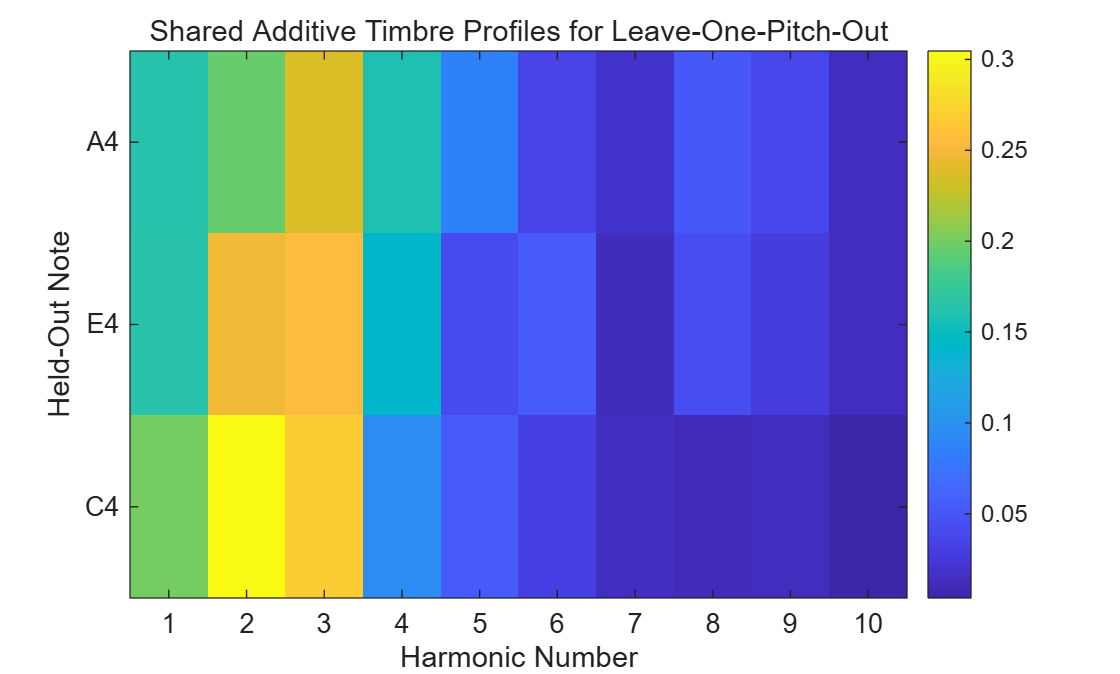



%% Shared Harmonic Timbre Profiles

figure;

imagesc( ...
    1:numHarmonicsLOPO, ...
    1:numFolds, ...
    sharedHarmonicProfiles);

colorbar;

xlabel('Harmonic Number');
ylabel('Held-Out Note');

title( ...
    'Shared Additive Timbre Profiles for Leave-One-Pitch-Out');

xticks(1:numHarmonicsLOPO);

yticks(1:numFolds);

yticklabels( ...
    {'A4','E4','C4'});


%% Save Leave-One-Pitch-Out Additive Results

csvFile = fullfile( ...
    resultsFolder, ...
    'LOPO_Additive_Shared_Harmonic_Profiles.csv');

writetable( ...
    LOPOHarmonicTable, ...
    csvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'LOPO_Additive_Shared_Harmonic_Profiles.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Leave-One-Pitch-Out FM Synthesis


% ---------------------------------------------------------
% Best independently fitted FM parameters
% obtained from the previous multi-start optimisation
%
% Order: C4, E4, A4
% ---------------------------------------------------------

fmCarrierRatios = [1.0000, 1.0000, 1.0000];

fmModulatorRatios = [
    1.4431
    1.4271
    1.3845
];

fmModulationIndices = [
    10.0000
    9.5705
    6.8822
];


% ---------------------------------------------------------
% Storage
% ---------------------------------------------------------

sharedCarrierRatios = zeros(numFolds,1);
sharedModulatorRatios = zeros(numFolds,1);
sharedModulationIndices = zeros(numFolds,1);

lopoFMFiles = cell(numFolds,1);


%% Fit Shared FM Timbre and Predict Held-Out Pitch

for fold = 1:numFolds

    trainIndices = trainingPairs(fold,:);
    testIndex = heldOutIndices(fold);


    % -----------------------------------------------------
    % Shared FM timbre parameters
    %
    % Only parameters from the two training notes are used.
    % -----------------------------------------------------

    sharedCarrierRatio = ...
        mean(fmCarrierRatios(trainIndices));

    sharedModulatorRatio = ...
        mean(fmModulatorRatios(trainIndices));

    sharedModulationIndex = ...
        mean(fmModulationIndices(trainIndices));


    sharedCarrierRatios(fold) = ...
        sharedCarrierRatio;

    sharedModulatorRatios(fold) = ...
        sharedModulatorRatio;

    sharedModulationIndices(fold) = ...
        sharedModulationIndex;


    % -----------------------------------------------------
    % Load held-out reference ONLY for:
    %
    % - sampling rate
    % - duration
    %
    % Its fitted FM parameters are NOT used.
    % -----------------------------------------------------

    [xHeldOut, fsHeldOut] = ...
        audioread(referenceFiles{testIndex});

    if size(xHeldOut,2) == 2
        xHeldOut = mean(xHeldOut,2);
    end

    heldOutLength = length(xHeldOut);


    % -----------------------------------------------------
    % Held-out target pitch
    % -----------------------------------------------------

    f0HeldOut = f0Values(testIndex);

    tHeldOut = ...
        (0:heldOutLength-1)' / fsHeldOut;


    % -----------------------------------------------------
    % Pitch-independent FM ratios
    %
    % fc = rc * f0
    % fm = rm * f0
    % -----------------------------------------------------

    carrierFrequency = ...
        sharedCarrierRatio * f0HeldOut;

    modulatorFrequency = ...
        sharedModulatorRatio * f0HeldOut;


    % -----------------------------------------------------
    % Use the shared temporal envelope learned from the same
    % two training notes in the Additive LOPO experiment.
    % -----------------------------------------------------

    sharedEnvelopeProfile = ...
        sharedEnvelopeProfiles(fold,:);

    sharedEnvelopeTime = ...
        linspace( ...
        0, ...
        1, ...
        normalisedEnvelopeLength);

    heldOutNormalisedTime = ...
        linspace( ...
        0, ...
        1, ...
        heldOutLength);


    heldOutEnvelope = ...
        interp1( ...
        sharedEnvelopeTime, ...
        sharedEnvelopeProfile, ...
        heldOutNormalisedTime, ...
        'linear')';

    heldOutEnvelope = ...
        max(heldOutEnvelope,0);


    % -----------------------------------------------------
    % Two-operator FM synthesis
    %
    % y(t) =
    % sin(2*pi*fc*t +
    %     I*sin(2*pi*fm*t))
    % -----------------------------------------------------

    yFMLOPO = sin( ...
        2*pi*carrierFrequency*tHeldOut + ...
        sharedModulationIndex * ...
        sin( ...
        2*pi*modulatorFrequency*tHeldOut));


    % -----------------------------------------------------
    % Apply shared temporal envelope
    % -----------------------------------------------------

    yFMLOPO = ...
        yFMLOPO .* heldOutEnvelope;


    % -----------------------------------------------------
    % Normalise
    % -----------------------------------------------------

    if max(abs(yFMLOPO)) > 0

        yFMLOPO = ...
            yFMLOPO / max(abs(yFMLOPO));

    end


    % -----------------------------------------------------
    % Save held-out FM audio
    % -----------------------------------------------------

    outputFile = fullfile( ...
        audioFolder, ...
        ['Flute_', ...
         notes{testIndex}, ...
         '_LOPO_FM.wav']);


    audiowrite( ...
        outputFile, ...
        yFMLOPO, ...
        fsHeldOut);


    lopoFMFiles{fold} = ...
        outputFile;

end


%% Leave-One-Pitch-Out FM Mapping Table

LOPOFMTable = table( ...
    TrainingNotes, ...
    HeldOutNote, ...
    lopoFMFiles, ...
    'VariableNames', ...
    { ...
    'Training_Notes', ...
    'Held_Out_Note', ...
    'Output_File' ...
    });

LOPOFMTable

LOPOFMTable = 3×3 table
    Training_Notes    Held_Out_Note                                     Output_File                                 
    ______________    _____________    _____________________________________________________________________________

     {'C4 + E4'}         {'A4'}        {'C:\Users\15023\Desktop\ELEC5305_Project\audio_output\Flute_A4_LOPO_FM.wav'}
     {'C4 + A4'}         {'E4'}        {'C:\Users\15023\Desktop\ELEC5305_Project\audio_output\Flute_E4_LOPO_FM.wav'}
     {'E4 + A4'}         {'C4'}        {'C:\Users\15023\Desktop\ELEC5305_Project\audio_output\Flute_C4_LOPO_FM.wav'}

	使用 Copilot 获取洞察




%% Shared FM Parameter Table

LOPOFMParameterTable = table( ...
    HeldOutNote, ...
    sharedCarrierRatios, ...
    sharedModulatorRatios, ...
    sharedModulationIndices, ...
    'VariableNames', ...
    { ...
    'Held_Out_Note', ...
    'Carrier_Ratio', ...
    'Modulator_Ratio', ...
    'Modulation_Index' ...
    });

LOPOFMParameterTable

LOPOFMParameterTable = 3×4 table
    Held_Out_Note    Carrier_Ratio    Modulator_Ratio    Modulation_Index
    _____________    _____________    _______________    ________________

       {'A4'}              1              1.4351              9.7852     
       {'E4'}              1              1.4138              8.4411     
       {'C4'}              1              1.4058              8.2264     

	使用 Copilot 获取洞察


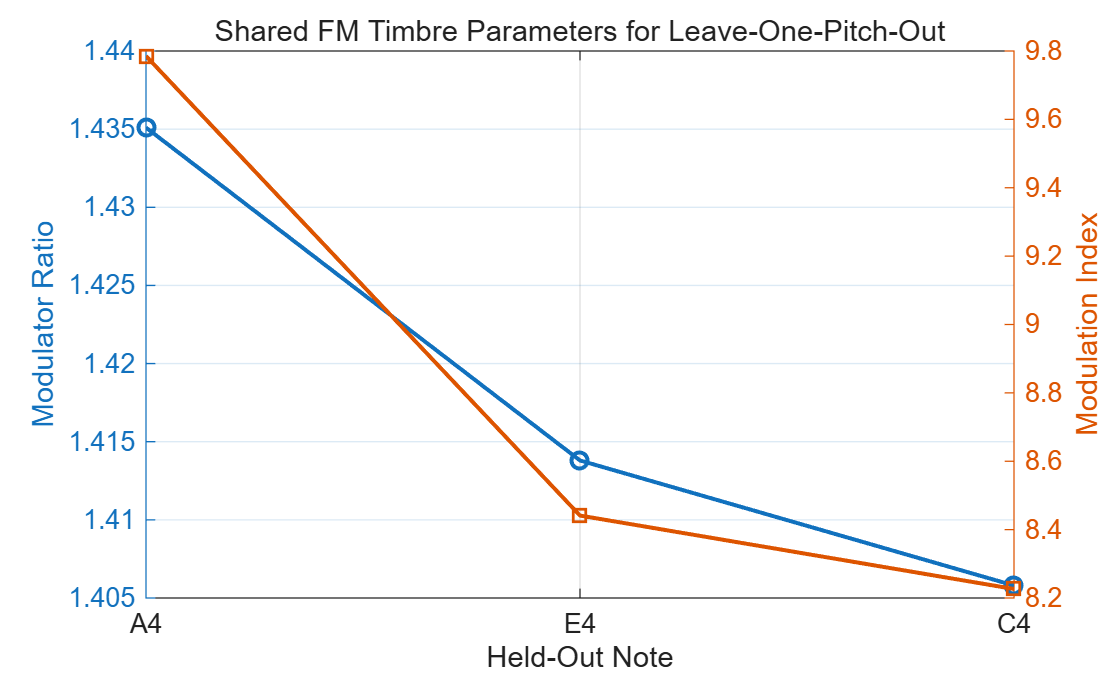



%% Shared FM Timbre Parameter Figure

figure;

yyaxis left

plot( ...
    1:numFolds, ...
    sharedModulatorRatios, ...
    '-o', ...
    'LineWidth', ...
    1.5);

ylabel('Modulator Ratio');


yyaxis right

plot( ...
    1:numFolds, ...
    sharedModulationIndices, ...
    '-s', ...
    'LineWidth', ...
    1.5);

ylabel('Modulation Index');


xlabel('Held-Out Note');

title( ...
    'Shared FM Timbre Parameters for Leave-One-Pitch-Out');

xticks(1:numFolds);

xticklabels( ...
    {'A4','E4','C4'});

grid on;


%% Save Leave-One-Pitch-Out FM Results

csvFile = fullfile( ...
    resultsFolder, ...
    'LOPO_FM_Shared_Parameters.csv');

writetable( ...
    LOPOFMParameterTable, ...
    csvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'LOPO_FM_Shared_Parameters.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Final Three-Model Quantitative Evaluation

% Time-Varying Additive vs Multi-Start FM vs Pretrained DDSP
%
% All signals are peak-normalised before evaluation so that differences in
% output gain do not dominate the comparison.

%% File paths

scriptPath = matlab.desktop.editor.getActiveFilename;

if isempty(scriptPath)
    scriptPath = mfilename('fullpath');
end

codeFolder = fileparts(scriptPath);
projectRoot = fileparts(codeFolder);

referenceFolder = fullfile(projectRoot, 'data', 'flute');
audioFolder = fullfile(projectRoot, 'audio_output');
resultsFolder = fullfile(projectRoot, 'results_02');

if ~exist(resultsFolder, 'dir')
    mkdir(resultsFolder);
end

notes = {'C4', 'E4', 'A4'};

referenceFiles = {
    fullfile(referenceFolder, 'Flute.nonvib.ff.C4.stereo.aif')
    fullfile(referenceFolder, 'Flute.nonvib.ff.E4.stereo.aif')
    fullfile(referenceFolder, 'Flute.nonvib.ff.A4.stereo.aif')
};

additiveFiles = {
    fullfile(audioFolder, 'Flute_C4_TimeVarying_Additive.wav')
    fullfile(audioFolder, 'Flute_E4_TimeVarying_Additive.wav')
    fullfile(audioFolder, 'Flute_A4_TimeVarying_Additive.wav')
};

fmFiles = {
    fullfile(audioFolder, 'Flute_C4_MultiStart_FM.wav')
    fullfile(audioFolder, 'Flute_E4_MultiStart_FM.wav')
    fullfile(audioFolder, 'Flute_A4_MultiStart_FM.wav')
};

ddspFiles = {
    fullfile(audioFolder, 'Flute_C4_DDSP.wav')
    fullfile(audioFolder, 'Flute_E4_DDSP.wav')
    fullfile(audioFolder, 'Flute_A4_DDSP.wav')
};

% Fundamental frequencies measured previously from the flute references.
f0Values = [260.79, 329.73, 442.25];


%% Metric storage

numNotes = length(notes);

Additive_LSD = zeros(numNotes,1);
FM_LSD       = zeros(numNotes,1);
DDSP_LSD     = zeros(numNotes,1);

Additive_MRSTFT = zeros(numNotes,1);
FM_MRSTFT       = zeros(numNotes,1);
DDSP_MRSTFT     = zeros(numNotes,1);

Additive_Harmonic = zeros(numNotes,1);
FM_Harmonic       = zeros(numNotes,1);
DDSP_Harmonic     = zeros(numNotes,1);

Additive_Envelope = zeros(numNotes,1);
FM_Envelope       = zeros(numNotes,1);
DDSP_Envelope     = zeros(numNotes,1);


%% Evaluate C4, E4 and A4

for i = 1:numNotes

    %% ----------------------------------------------------
    % Load reference
    % -----------------------------------------------------

    [reference, fsReference] = audioread(referenceFiles{i});

    if size(reference,2) == 2
        reference = mean(reference,2);
    end


    %% ----------------------------------------------------
    % Load synthesis outputs
    % -----------------------------------------------------

    [additive, fsAdditive] = audioread(additiveFiles{i});

    if size(additive,2) == 2
        additive = mean(additive,2);
    end


    [fm, fsFM] = audioread(fmFiles{i});

    if size(fm,2) == 2
        fm = mean(fm,2);
    end


    [ddsp, fsDDSP] = audioread(ddspFiles{i});

    if size(ddsp,2) == 2
        ddsp = mean(ddsp,2);
    end


    %% ----------------------------------------------------
    % Resample all synthesis outputs to reference Fs
    % -----------------------------------------------------

    if fsAdditive ~= fsReference
        additive = resample(additive, fsReference, fsAdditive);
    end

    if fsFM ~= fsReference
        fm = resample(fm, fsReference, fsFM);
    end

    if fsDDSP ~= fsReference
        ddsp = resample(ddsp, fsReference, fsDDSP);
    end


    %% ----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min([
        length(reference)
        length(additive)
        length(fm)
        length(ddsp)
    ]);

    reference = reference(1:minLength);
    additive  = additive(1:minLength);
    fm        = fm(1:minLength);
    ddsp      = ddsp(1:minLength);


    %% ----------------------------------------------------
    % Peak normalisation
    % -----------------------------------------------------

    reference = reference / (max(abs(reference)) + eps);
    additive  = additive  / (max(abs(additive))  + eps);
    fm        = fm        / (max(abs(fm))        + eps);
    ddsp      = ddsp      / (max(abs(ddsp))      + eps);


    %% ====================================================
    % 1. LOG-SPECTRAL DISTANCE
    % =====================================================

    NFFT = 2^nextpow2(minLength);

    refSpectrum = abs(fft(reference, NFFT));
    addSpectrum = abs(fft(additive,  NFFT));
    fmSpectrum  = abs(fft(fm,        NFFT));
    ddspSpectrum = abs(fft(ddsp,     NFFT));

    halfN = floor(NFFT/2) + 1;

    refSpectrum  = refSpectrum(1:halfN);
    addSpectrum  = addSpectrum(1:halfN);
    fmSpectrum   = fmSpectrum(1:halfN);
    ddspSpectrum = ddspSpectrum(1:halfN);

    frequency = (0:halfN-1)' * fsReference / NFFT;

    freqMask = frequency <= 5000;

    refSpectrum  = refSpectrum(freqMask);
    addSpectrum  = addSpectrum(freqMask);
    fmSpectrum   = fmSpectrum(freqMask);
    ddspSpectrum = ddspSpectrum(freqMask);

    % Normalise spectra before log comparison
    refSpectrum  = refSpectrum  / (max(refSpectrum)  + eps);
    addSpectrum  = addSpectrum  / (max(addSpectrum)  + eps);
    fmSpectrum   = fmSpectrum   / (max(fmSpectrum)   + eps);
    ddspSpectrum = ddspSpectrum / (max(ddspSpectrum) + eps);

    refDB  = 20*log10(refSpectrum  + 1e-8);
    addDB  = 20*log10(addSpectrum  + 1e-8);
    fmDB   = 20*log10(fmSpectrum   + 1e-8);
    ddspDB = 20*log10(ddspSpectrum + 1e-8);

    Additive_LSD(i) = sqrt(mean((refDB - addDB).^2));
    FM_LSD(i)       = sqrt(mean((refDB - fmDB).^2));
    DDSP_LSD(i)     = sqrt(mean((refDB - ddspDB).^2));


    %% ====================================================
    % 2. MULTI-RESOLUTION STFT ERROR
    % =====================================================

    windowSizes = [512 1024 2048];

    addMR = zeros(length(windowSizes),1);
    fmMR = zeros(length(windowSizes),1);
    ddspMR = zeros(length(windowSizes),1);

    for w = 1:length(windowSizes)

        windowLength = windowSizes(w);
        overlapLength = round(0.75 * windowLength);
        window = hann(windowLength, 'periodic');

        Sref = spectrogram( ...
            reference, ...
            window, ...
            overlapLength, ...
            windowLength, ...
            fsReference);

        Sadd = spectrogram( ...
            additive, ...
            window, ...
            overlapLength, ...
            windowLength, ...
            fsReference);

        Sfm = spectrogram( ...
            fm, ...
            window, ...
            overlapLength, ...
            windowLength, ...
            fsReference);

        Sddsp = spectrogram( ...
            ddsp, ...
            window, ...
            overlapLength, ...
            windowLength, ...
            fsReference);

        Mref  = abs(Sref);
        Madd  = abs(Sadd);
        Mfm   = abs(Sfm);
        Mddsp = abs(Sddsp);

        refNorm = norm(Mref, 'fro') + eps;

        addMR(w) = norm(Mref - Madd, 'fro') / refNorm;
        fmMR(w)  = norm(Mref - Mfm,  'fro') / refNorm;
        ddspMR(w)= norm(Mref - Mddsp,'fro') / refNorm;

    end

    Additive_MRSTFT(i) = mean(addMR);
    FM_MRSTFT(i)       = mean(fmMR);
    DDSP_MRSTFT(i)     = mean(ddspMR);


    %% ====================================================
    % 3. HARMONIC AMPLITUDE ERROR
    % =====================================================

    numHarmonics = 10;
    searchWidthHz = 20;

    harmonicRef  = zeros(numHarmonics,1);
    harmonicAdd  = zeros(numHarmonics,1);
    harmonicFM   = zeros(numHarmonics,1);
    harmonicDDSP = zeros(numHarmonics,1);

    frequencyFull = (0:halfN-1)' * fsReference / NFFT;

    refFull  = abs(fft(reference, NFFT));
    addFull  = abs(fft(additive,  NFFT));
    fmFull   = abs(fft(fm,        NFFT));
    ddspFull = abs(fft(ddsp,      NFFT));

    refFull  = refFull(1:halfN);
    addFull  = addFull(1:halfN);
    fmFull   = fmFull(1:halfN);
    ddspFull = ddspFull(1:halfN);

    for h = 1:numHarmonics

        targetFrequency = h * f0Values(i);

        harmonicMask = ...
            frequencyFull >= targetFrequency - searchWidthHz & ...
            frequencyFull <= targetFrequency + searchWidthHz;

        harmonicRef(h)  = max(refFull(harmonicMask));
        harmonicAdd(h)  = max(addFull(harmonicMask));
        harmonicFM(h)   = max(fmFull(harmonicMask));
        harmonicDDSP(h) = max(ddspFull(harmonicMask));

    end

    % Normalise harmonic profiles
    harmonicRef  = harmonicRef  / (max(harmonicRef)  + eps);
    harmonicAdd  = harmonicAdd  / (max(harmonicAdd)  + eps);
    harmonicFM   = harmonicFM   / (max(harmonicFM)   + eps);
    harmonicDDSP = harmonicDDSP / (max(harmonicDDSP) + eps);

    Additive_Harmonic(i) = mean(abs(harmonicRef - harmonicAdd));
    FM_Harmonic(i)       = mean(abs(harmonicRef - harmonicFM));
    DDSP_Harmonic(i)     = mean(abs(harmonicRef - harmonicDDSP));


    %% ====================================================
    % 4. TEMPORAL-ENVELOPE ERROR
    % =====================================================

    envelopeWindow = max(1, round(0.020 * fsReference));

    refEnvelope = movmean(abs(reference), envelopeWindow);
    addEnvelope = movmean(abs(additive),  envelopeWindow);
    fmEnvelope  = movmean(abs(fm),        envelopeWindow);
    ddspEnvelope = movmean(abs(ddsp),     envelopeWindow);

    refEnvelope  = refEnvelope  / (max(refEnvelope)  + eps);
    addEnvelope  = addEnvelope  / (max(addEnvelope)  + eps);
    fmEnvelope   = fmEnvelope   / (max(fmEnvelope)   + eps);
    ddspEnvelope = ddspEnvelope / (max(ddspEnvelope) + eps);

    Additive_Envelope(i) = mean(abs(refEnvelope - addEnvelope));
    FM_Envelope(i)       = mean(abs(refEnvelope - fmEnvelope));
    DDSP_Envelope(i)     = mean(abs(refEnvelope - ddspEnvelope));

end


%% Final three-model table

ThreeModelEvaluationTable = table( ...
    notes', ...
    Additive_LSD, ...
    FM_LSD, ...
    DDSP_LSD, ...
    Additive_MRSTFT, ...
    FM_MRSTFT, ...
    DDSP_MRSTFT, ...
    Additive_Harmonic, ...
    FM_Harmonic, ...
    DDSP_Harmonic, ...
    Additive_Envelope, ...
    FM_Envelope, ...
    DDSP_Envelope, ...
    'VariableNames', { ...
    'Note', ...
    'Additive_LSD_dB', ...
    'FM_LSD_dB', ...
    'DDSP_LSD_dB', ...
    'Additive_MRSTFT_Error', ...
    'FM_MRSTFT_Error', ...
    'DDSP_MRSTFT_Error', ...
    'Additive_Harmonic_Error', ...
    'FM_Harmonic_Error', ...
    'DDSP_Harmonic_Error', ...
    'Additive_Envelope_Error', ...
    'FM_Envelope_Error', ...
    'DDSP_Envelope_Error'});

ThreeModelEvaluationTable

ThreeModelEvaluationTable = 3×13 table
     Note     Additive_LSD_dB    FM_LSD_dB    DDSP_LSD_dB    Additive_MRSTFT_Error    FM_MRSTFT_Error    DDSP_MRSTFT_Error    Additive_Harmonic_Error    FM_Harmonic_Error    DDSP_Harmonic_Error    Additive_Envelope_Error    FM_Envelope_Error    DDSP_Envelope_Error
    ______    _______________    _________    ___________    _____________________    _______________    _________________    _______________________    _________________    ___________________    _______________________    _________________    ___________________

    {'C4'}        46.102          23.033        17.972              0.15943                 1.52              0.89479                0.075323                 0.36311               0.34914                 0.035225                0.022414               0.41641      
    {'E4'}        44.148          23.577        23.744             0.070729                1.728              0.84211                0.084436                 0.35773



%% Mean results across the three target pitches

ThreeModelMeanTable = table( ...
    mean(Additive_LSD), ...
    mean(FM_LSD), ...
    mean(DDSP_LSD), ...
    mean(Additive_MRSTFT), ...
    mean(FM_MRSTFT), ...
    mean(DDSP_MRSTFT), ...
    mean(Additive_Harmonic), ...
    mean(FM_Harmonic), ...
    mean(DDSP_Harmonic), ...
    mean(Additive_Envelope), ...
    mean(FM_Envelope), ...
    mean(DDSP_Envelope), ...
    'VariableNames', { ...
    'Mean_Additive_LSD_dB', ...
    'Mean_FM_LSD_dB', ...
    'Mean_DDSP_LSD_dB', ...
    'Mean_Additive_MRSTFT_Error', ...
    'Mean_FM_MRSTFT_Error', ...
    'Mean_DDSP_MRSTFT_Error', ...
    'Mean_Additive_Harmonic_Error', ...
    'Mean_FM_Harmonic_Error', ...
    'Mean_DDSP_Harmonic_Error', ...
    'Mean_Additive_Envelope_Error', ...
    'Mean_FM_Envelope_Error', ...
    'Mean_DDSP_Envelope_Error'});

ThreeModelMeanTable

ThreeModelMeanTable = 1×12 table
    Mean_Additive_LSD_dB    Mean_FM_LSD_dB    Mean_DDSP_LSD_dB    Mean_Additive_MRSTFT_Error    Mean_FM_MRSTFT_Error    Mean_DDSP_MRSTFT_Error    Mean_Additive_Harmonic_Error    Mean_FM_Harmonic_Error    Mean_DDSP_Harmonic_Error    Mean_Additive_Envelope_Error    Mean_FM_Envelope_Error    Mean_DDSP_Envelope_Error
    ____________________    ______________    ________________    __________________________    ____________________    ______________________    ____________________________    ______________________    ________________________    ____________________________    ______________________    ________________________

           43.604               23.905             21.317                  0.10783                     1.6082                  0.86653                      0.067737                     0.32803                    0.29121                       0.035856                     0.021446                   0.38069         

	

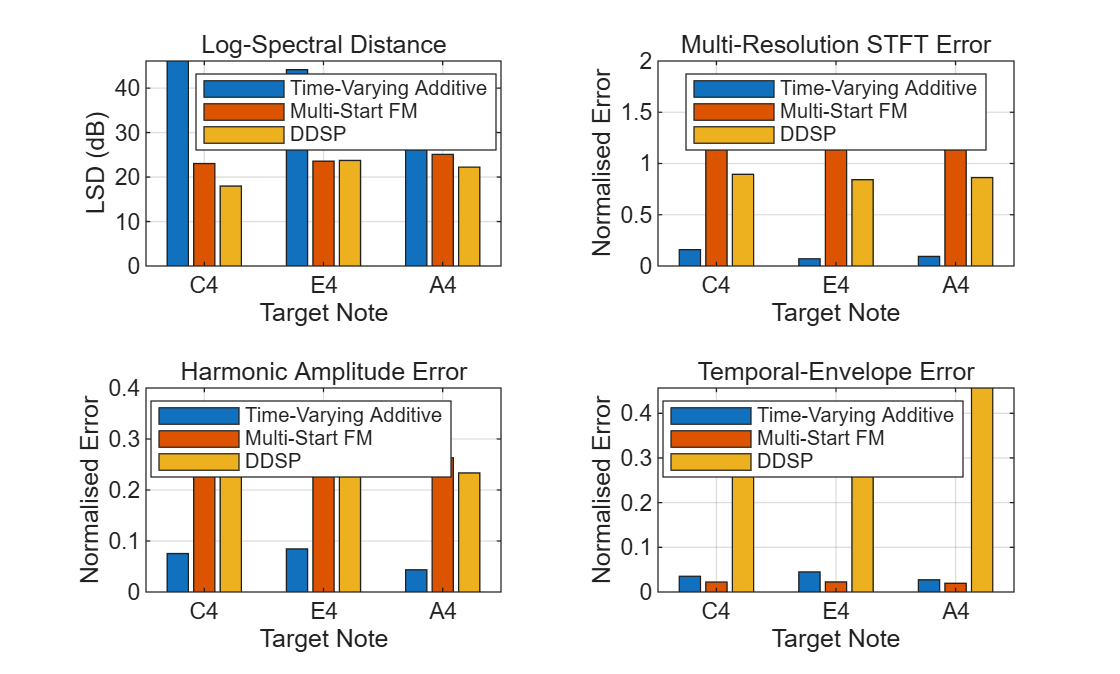



%% Final comparison figure

figure;

tiledlayout(2,2);

nexttile;

bar([ ...
    Additive_LSD ...
    FM_LSD ...
    DDSP_LSD]);

xticklabels(notes);
xlabel('Target Note');
ylabel('LSD (dB)');
title('Log-Spectral Distance');

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'DDSP', ...
    'Location', 'best');

grid on;


nexttile;

bar([ ...
    Additive_MRSTFT ...
    FM_MRSTFT ...
    DDSP_MRSTFT]);

xticklabels(notes);
xlabel('Target Note');
ylabel('Normalised Error');
title('Multi-Resolution STFT Error');

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'DDSP', ...
    'Location', 'best');

grid on;


nexttile;

bar([ ...
    Additive_Harmonic ...
    FM_Harmonic ...
    DDSP_Harmonic]);

xticklabels(notes);
xlabel('Target Note');
ylabel('Normalised Error');
title('Harmonic Amplitude Error');

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'DDSP', ...
    'Location', 'best');

grid on;


nexttile;

bar([ ...
    Additive_Envelope ...
    FM_Envelope ...
    DDSP_Envelope]);

xticklabels(notes);
xlabel('Target Note');
ylabel('Normalised Error');
title('Temporal-Envelope Error');

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'DDSP', ...
    'Location', 'best');

grid on;


%% Save final results

tableFile = fullfile( ...
    resultsFolder, ...
    'Final_ThreeModel_Evaluation.csv');

meanTableFile = fullfile( ...
    resultsFolder, ...
    'Final_ThreeModel_Mean.csv');

figureFile = fullfile( ...
    resultsFolder, ...
    'Final_ThreeModel_Comparison.png');

writetable( ...
    ThreeModelEvaluationTable, ...
    tableFile);

writetable( ...
    ThreeModelMeanTable, ...
    meanTableFile);

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', 200);

### Three-Model Residual Spectral Analysis

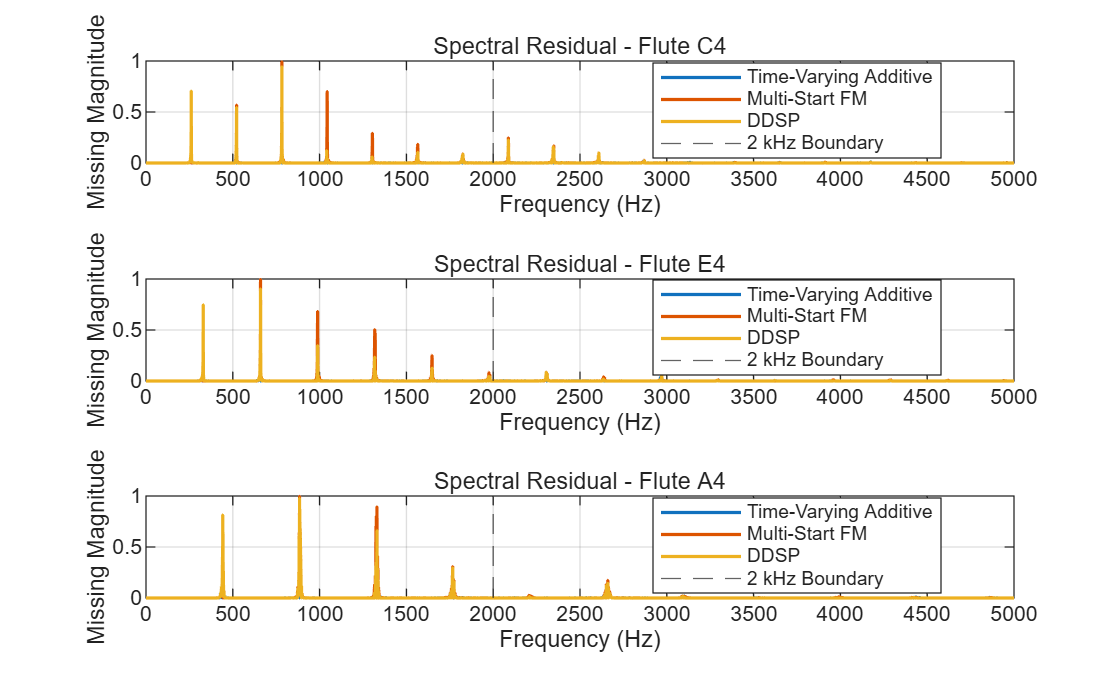

% Compare spectral information missing from:
% Time-Varying Additive, Multi-Start FM and pretrained DDSP.
%
% Lower missing spectral energy indicates that more of the reference
% spectral structure has been reconstructed.

numNotes = length(notes);

Additive_Total_Missing = zeros(numNotes,1);
FM_Total_Missing       = zeros(numNotes,1);
DDSP_Total_Missing     = zeros(numNotes,1);

Additive_HF_Missing = zeros(numNotes,1);
FM_HF_Missing       = zeros(numNotes,1);
DDSP_HF_Missing     = zeros(numNotes,1);


figure;
tiledlayout(3,1);

for i = 1:numNotes

    %% Load audio

    [reference, fsReference] = audioread(referenceFiles{i});
    [additive, fsAdditive]   = audioread(additiveFiles{i});
    [fm, fsFM]               = audioread(fmFiles{i});
    [ddsp, fsDDSP]           = audioread(ddspFiles{i});

    if size(reference,2) == 2
        reference = mean(reference,2);
    end

    if size(additive,2) == 2
        additive = mean(additive,2);
    end

    if size(fm,2) == 2
        fm = mean(fm,2);
    end

    if size(ddsp,2) == 2
        ddsp = mean(ddsp,2);
    end


    %% Resample to reference sampling rate

    if fsAdditive ~= fsReference
        additive = resample(additive, fsReference, fsAdditive);
    end

    if fsFM ~= fsReference
        fm = resample(fm, fsReference, fsFM);
    end

    if fsDDSP ~= fsReference
        ddsp = resample(ddsp, fsReference, fsDDSP);
    end


    %% Match lengths

    minLength = min([
        length(reference)
        length(additive)
        length(fm)
        length(ddsp)
    ]);

    reference = reference(1:minLength);
    additive  = additive(1:minLength);
    fm        = fm(1:minLength);
    ddsp      = ddsp(1:minLength);


    %% Peak normalisation

    reference = reference / (max(abs(reference)) + eps);
    additive  = additive  / (max(abs(additive))  + eps);
    fm        = fm        / (max(abs(fm))        + eps);
    ddsp      = ddsp      / (max(abs(ddsp))      + eps);


    %% FFT

    NFFT = 2^nextpow2(minLength);

    refSpectrum  = abs(fft(reference, NFFT));
    addSpectrum  = abs(fft(additive, NFFT));
    fmSpectrum   = abs(fft(fm, NFFT));
    ddspSpectrum = abs(fft(ddsp, NFFT));

    halfN = floor(NFFT/2) + 1;

    refSpectrum  = refSpectrum(1:halfN);
    addSpectrum  = addSpectrum(1:halfN);
    fmSpectrum   = fmSpectrum(1:halfN);
    ddspSpectrum = ddspSpectrum(1:halfN);

    frequency = (0:halfN-1)' * fsReference / NFFT;


    %% Restrict analysis to 0-5 kHz

    analysisMask = frequency <= 5000;

    f = frequency(analysisMask);

    refSpectrum  = refSpectrum(analysisMask);
    addSpectrum  = addSpectrum(analysisMask);
    fmSpectrum   = fmSpectrum(analysisMask);
    ddspSpectrum = ddspSpectrum(analysisMask);


    %% Normalise spectra

    refSpectrum  = refSpectrum  / (max(refSpectrum)  + eps);
    addSpectrum  = addSpectrum  / (max(addSpectrum)  + eps);
    fmSpectrum   = fmSpectrum   / (max(fmSpectrum)   + eps);
    ddspSpectrum = ddspSpectrum / (max(ddspSpectrum) + eps);


    %% Missing spectral energy

    addMissing  = max(refSpectrum - addSpectrum, 0);
    fmMissing   = max(refSpectrum - fmSpectrum, 0);
    ddspMissing = max(refSpectrum - ddspSpectrum, 0);

    referenceEnergy = sum(refSpectrum.^2) + eps;

    Additive_Total_Missing(i) = ...
        sum(addMissing.^2) / referenceEnergy;

    FM_Total_Missing(i) = ...
        sum(fmMissing.^2) / referenceEnergy;

    DDSP_Total_Missing(i) = ...
        sum(ddspMissing.^2) / referenceEnergy;


    %% High-frequency missing energy: 2-5 kHz

    hfMask = f >= 2000 & f <= 5000;

    referenceHFEnergy = ...
        sum(refSpectrum(hfMask).^2) + eps;

    Additive_HF_Missing(i) = ...
        sum(addMissing(hfMask).^2) / referenceHFEnergy;

    FM_HF_Missing(i) = ...
        sum(fmMissing(hfMask).^2) / referenceHFEnergy;

    DDSP_HF_Missing(i) = ...
        sum(ddspMissing(hfMask).^2) / referenceHFEnergy;


    %% Residual spectral curves

    nexttile;

    plot(f, addMissing, 'LineWidth', 1.2);
    hold on;

    plot(f, fmMissing, 'LineWidth', 1.2);
    plot(f, ddspMissing, 'LineWidth', 1.2);

    xline(2000, '--');

    xlim([0 5000]);

    xlabel('Frequency (Hz)');
    ylabel('Missing Magnitude');

    title(['Spectral Residual - Flute ', notes{i}]);

    legend( ...
        'Time-Varying Additive', ...
        'Multi-Start FM', ...
        'DDSP', ...
        '2 kHz Boundary', ...
        'Location', 'best');

    grid on;
    hold off;

end



%% Residual results table

ThreeModelResidualTable = table( ...
    notes', ...
    Additive_Total_Missing, ...
    FM_Total_Missing, ...
    DDSP_Total_Missing, ...
    Additive_HF_Missing, ...
    FM_HF_Missing, ...
    DDSP_HF_Missing, ...
    'VariableNames', { ...
    'Note', ...
    'Additive_Total_Missing', ...
    'FM_Total_Missing', ...
    'DDSP_Total_Missing', ...
    'Additive_HF_Missing', ...
    'FM_HF_Missing', ...
    'DDSP_HF_Missing'});

ThreeModelResidualTable

ThreeModelResidualTable = 3×7 table
     Note     Additive_Total_Missing    FM_Total_Missing    DDSP_Total_Missing    Additive_HF_Missing    FM_HF_Missing    DDSP_HF_Missing
    ______    ______________________    ________________    __________________    ___________________    _____________    _______________

    {'C4'}           0.22506                0.87763              0.63997                0.52183             0.98223           0.73587    
    {'E4'}           0.42649                0.87746              0.48738                0.70859             0.83684           0.54529    
    {'A4'}           0.68693                0.91669              0.66857                0.88456             0.98794           0.45587    

	使用 Copilot 获取洞察




%% Mean residual results

ThreeModelResidualMeanTable = table( ...
    mean(Additive_Total_Missing), ...
    mean(FM_Total_Missing), ...
    mean(DDSP_Total_Missing), ...
    mean(Additive_HF_Missing), ...
    mean(FM_HF_Missing), ...
    mean(DDSP_HF_Missing), ...
    'VariableNames', { ...
    'Mean_Additive_Total_Missing', ...
    'Mean_FM_Total_Missing', ...
    'Mean_DDSP_Total_Missing', ...
    'Mean_Additive_HF_Missing', ...
    'Mean_FM_HF_Missing', ...
    'Mean_DDSP_HF_Missing'});

ThreeModelResidualMeanTable

ThreeModelResidualMeanTable = 1×6 table
    Mean_Additive_Total_Missing    Mean_FM_Total_Missing    Mean_DDSP_Total_Missing    Mean_Additive_HF_Missing    Mean_FM_HF_Missing    Mean_DDSP_HF_Missing
    ___________________________    _____________________    _______________________    ________________________    __________________    ____________________

              0.44616                     0.89059                   0.59864                     0.705                   0.93567                0.57901       

	使用 Copilot 获取洞察


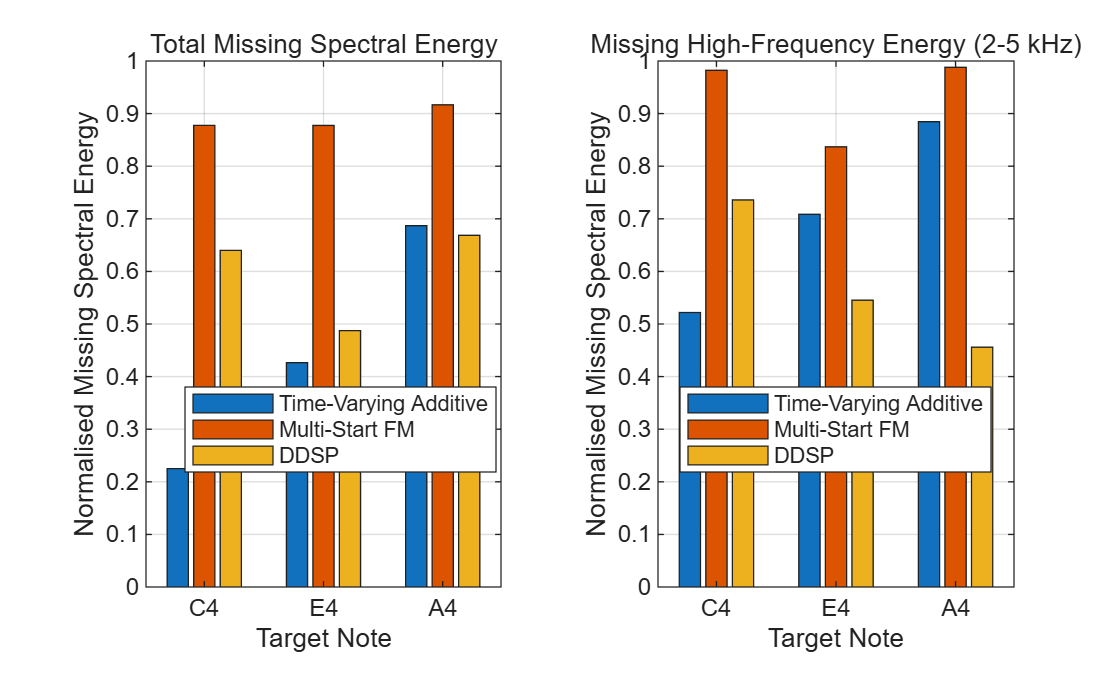



%% Summary figure

figure;

tiledlayout(1,2);

nexttile;

bar([
    Additive_Total_Missing ...
    FM_Total_Missing ...
    DDSP_Total_Missing
]);

xticklabels(notes);
xlabel('Target Note');
ylabel('Normalised Missing Spectral Energy');
title('Total Missing Spectral Energy');

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'DDSP', ...
    'Location', 'best');

grid on;


nexttile;

bar([
    Additive_HF_Missing ...
    FM_HF_Missing ...
    DDSP_HF_Missing
]);

xticklabels(notes);
xlabel('Target Note');
ylabel('Normalised Missing Spectral Energy');
title('Missing High-Frequency Energy (2-5 kHz)');

legend( ...
    'Time-Varying Additive', ...
    'Multi-Start FM', ...
    'DDSP', ...
    'Location', 'best');

grid on;


%% Save results

residualTableFile = fullfile( ...
    resultsFolder, ...
    'Final_ThreeModel_Residual_Results.csv');

residualMeanFile = fullfile( ...
    resultsFolder, ...
    'Final_ThreeModel_Residual_Mean.csv');

residualFigureFile = fullfile( ...
    resultsFolder, ...
    'Final_ThreeModel_Residual_Comparison.png');

writetable( ...
    ThreeModelResidualTable, ...
    residualTableFile);

writetable( ...
    ThreeModelResidualMeanTable, ...
    residualMeanFile);

exportgraphics( ...
    gcf, ...
    residualFigureFile, ...
    'Resolution', 200);

### Leave-One-Pitch-Out Quantitative Evaluation


% ---------------------------------------------------------
% LOPO audio files in C4 / E4 / A4 order
% ---------------------------------------------------------

lopoAdditiveEvalFiles = {
    fullfile(audioFolder, 'Flute_C4_LOPO_Additive.wav')
    fullfile(audioFolder, 'Flute_E4_LOPO_Additive.wav')
    fullfile(audioFolder, 'Flute_A4_LOPO_Additive.wav')
};

lopoFMEvalFiles = {
    fullfile(audioFolder, 'Flute_C4_LOPO_FM.wav')
    fullfile(audioFolder, 'Flute_E4_LOPO_FM.wav')
    fullfile(audioFolder, 'Flute_A4_LOPO_FM.wav')
};


% ---------------------------------------------------------
% Evaluation settings
% ---------------------------------------------------------

numNotes = length(notes);

maxEvalFrequency = 5000;

numHarmonicsLOPOEval = 10;
harmonicSearchRangeHz = 20;

envelopeWindowSeconds = 0.02;

% LSD settings
lsdWindowLength = 2048;
lsdOverlapLength = 1536;
lsdNfft = 4096;

% Multi-resolution STFT settings
mrWindowLengths = [512, 2048, 8192];
mrNfftValues = [1024, 4096, 16384];

numResolutions = length(mrWindowLengths);


% ---------------------------------------------------------
% Storage
% ---------------------------------------------------------

lopoAdditiveLSD = zeros(numNotes,1);
lopoFMLSD       = zeros(numNotes,1);

lopoAdditiveMR = zeros(numNotes,numResolutions);
lopoFMMR       = zeros(numNotes,numResolutions);

lopoAdditiveHarmonicError = zeros(numNotes,1);
lopoFMHarmonicError       = zeros(numNotes,1);

lopoAdditiveEnvelopeError = zeros(numNotes,1);
lopoFMEnvelopeError       = zeros(numNotes,1);


%% Evaluate C4, E4 and A4

for i = 1:numNotes

    % =====================================================
    % Load Audio
    % =====================================================

    [xRef, fsRef] = ...
        audioread(referenceFiles{i});

    [xAdd, fsAdd] = ...
        audioread(lopoAdditiveEvalFiles{i});

    [xFM, fsFM] = ...
        audioread(lopoFMEvalFiles{i});


    % =====================================================
    % Convert to Mono
    % =====================================================

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % =====================================================
    % Match Sampling Rates
    % =====================================================

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % =====================================================
    % Match Lengths
    % =====================================================

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % =====================================================
    % Normalise
    % =====================================================

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    %% ====================================================
    % 1. Log-Spectral Distance
    % =====================================================

    [Sref, F, ~] = spectrogram( ...
        xRef, ...
        hann(lsdWindowLength), ...
        lsdOverlapLength, ...
        lsdNfft, ...
        fs);

    [Sadd, ~, ~] = spectrogram( ...
        xAdd, ...
        hann(lsdWindowLength), ...
        lsdOverlapLength, ...
        lsdNfft, ...
        fs);

    [Sfm, ~, ~] = spectrogram( ...
        xFM, ...
        hann(lsdWindowLength), ...
        lsdOverlapLength, ...
        lsdNfft, ...
        fs);


    freqMask = F <= maxEvalFrequency;

    refMag = abs(Sref(freqMask,:));
    addMag = abs(Sadd(freqMask,:));
    fmMag  = abs(Sfm(freqMask,:));

    epsilon = 1e-8;

    refLog = 20 * log10(refMag + epsilon);
    addLog = 20 * log10(addMag + epsilon);
    fmLog  = 20 * log10(fmMag  + epsilon);

    addFrameLSD = sqrt( ...
        mean((refLog - addLog).^2,1));

    fmFrameLSD = sqrt( ...
        mean((refLog - fmLog).^2,1));

    lopoAdditiveLSD(i) = mean(addFrameLSD);
    lopoFMLSD(i)       = mean(fmFrameLSD);


    %% ====================================================
    % 2. Multi-Resolution STFT Error
    % =====================================================

    for r = 1:numResolutions

        windowLength = ...
            mrWindowLengths(r);

        overlapLength = ...
            round(0.75 * windowLength);

        nfft = ...
            mrNfftValues(r);


        [SrefMR, FMR, ~] = spectrogram( ...
            xRef, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);

        [SaddMR, ~, ~] = spectrogram( ...
            xAdd, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);

        [SfmMR, ~, ~] = spectrogram( ...
            xFM, ...
            hann(windowLength), ...
            overlapLength, ...
            nfft, ...
            fs);


        freqMaskMR = ...
            FMR <= maxEvalFrequency;

        refMagMR = ...
            abs(SrefMR(freqMaskMR,:));

        addMagMR = ...
            abs(SaddMR(freqMaskMR,:));

        fmMagMR = ...
            abs(SfmMR(freqMaskMR,:));


        referenceEnergy = ...
            norm(refMagMR,'fro') + 1e-12;


        lopoAdditiveMR(i,r) = ...
            norm( ...
            refMagMR - addMagMR, ...
            'fro') / ...
            referenceEnergy;


        lopoFMMR(i,r) = ...
            norm( ...
            refMagMR - fmMagMR, ...
            'fro') / ...
            referenceEnergy;

    end


    %% ====================================================
    % 3. Harmonic Amplitude Error
    % =====================================================

    signalLength = length(xRef);

    nfftHarmonic = ...
        4 * 2^nextpow2(signalLength);

    analysisWindow = ...
        hann(signalLength);


    Xref = fft( ...
        xRef .* analysisWindow, ...
        nfftHarmonic);

    Xadd = fft( ...
        xAdd .* analysisWindow, ...
        nfftHarmonic);

    Xfm = fft( ...
        xFM .* analysisWindow, ...
        nfftHarmonic);


    halfLength = ...
        floor(nfftHarmonic/2) + 1;


    refSpectrum = ...
        abs(Xref(1:halfLength));

    addSpectrum = ...
        abs(Xadd(1:halfLength));

    fmSpectrum = ...
        abs(Xfm(1:halfLength));


    frequencyAxis = ...
        (0:halfLength-1)' * ...
        fs / nfftHarmonic;


    f0 = f0Values(i);


    refHarmonics = ...
        zeros(1,numHarmonicsLOPOEval);

    addHarmonics = ...
        zeros(1,numHarmonicsLOPOEval);

    fmHarmonics = ...
        zeros(1,numHarmonicsLOPOEval);


    for h = 1:numHarmonicsLOPOEval

        targetFrequency = h * f0;

        searchMask = ...
            frequencyAxis >= ...
            (targetFrequency - ...
             harmonicSearchRangeHz) & ...
            frequencyAxis <= ...
            (targetFrequency + ...
             harmonicSearchRangeHz);


        if any(searchMask)

            refHarmonics(h) = ...
                max(refSpectrum(searchMask));

            addHarmonics(h) = ...
                max(addSpectrum(searchMask));

            fmHarmonics(h) = ...
                max(fmSpectrum(searchMask));

        end

    end


    % Relative harmonic distributions

    if sum(refHarmonics) > 0
        refHarmonics = ...
            refHarmonics / ...
            sum(refHarmonics);
    end

    if sum(addHarmonics) > 0
        addHarmonics = ...
            addHarmonics / ...
            sum(addHarmonics);
    end

    if sum(fmHarmonics) > 0
        fmHarmonics = ...
            fmHarmonics / ...
            sum(fmHarmonics);
    end


    lopoAdditiveHarmonicError(i) = ...
        sqrt( ...
        mean( ...
        (refHarmonics - ...
         addHarmonics).^2));


    lopoFMHarmonicError(i) = ...
        sqrt( ...
        mean( ...
        (refHarmonics - ...
         fmHarmonics).^2));


    %% ====================================================
    % 4. Temporal-Envelope Error
    % =====================================================

    envelopeWindow = ...
        max(1, ...
        round( ...
        envelopeWindowSeconds * fs));


    refEnvelope = sqrt( ...
        movmean( ...
        xRef.^2, ...
        envelopeWindow));

    addEnvelope = sqrt( ...
        movmean( ...
        xAdd.^2, ...
        envelopeWindow));

    fmEnvelope = sqrt( ...
        movmean( ...
        xFM.^2, ...
        envelopeWindow));


    if max(refEnvelope) > 0
        refEnvelope = ...
            refEnvelope / ...
            max(refEnvelope);
    end

    if max(addEnvelope) > 0
        addEnvelope = ...
            addEnvelope / ...
            max(addEnvelope);
    end

    if max(fmEnvelope) > 0
        fmEnvelope = ...
            fmEnvelope / ...
            max(fmEnvelope);
    end


    lopoAdditiveEnvelopeError(i) = ...
        sqrt( ...
        mean( ...
        (refEnvelope - ...
         addEnvelope).^2));


    lopoFMEnvelopeError(i) = ...
        sqrt( ...
        mean( ...
        (refEnvelope - ...
         fmEnvelope).^2));

end


%% Combined Multi-Resolution Error

lopoAdditiveMRMean = ...
    mean(lopoAdditiveMR,2);

lopoFMMRMean = ...
    mean(lopoFMMR,2);


%% LOPO Results Table

LOPOEvaluationTable = table( ...
    notes', ...
    lopoAdditiveLSD, ...
    lopoFMLSD, ...
    lopoAdditiveMRMean, ...
    lopoFMMRMean, ...
    lopoAdditiveHarmonicError, ...
    lopoFMHarmonicError, ...
    lopoAdditiveEnvelopeError, ...
    lopoFMEnvelopeError, ...
    'VariableNames', ...
    { ...
    'Note', ...
    'Additive_LSD_dB', ...
    'FM_LSD_dB', ...
    'Additive_MRSTFT_Error', ...
    'FM_MRSTFT_Error', ...
    'Additive_Harmonic_Error', ...
    'FM_Harmonic_Error', ...
    'Additive_Envelope_Error', ...
    'FM_Envelope_Error' ...
    });

LOPOEvaluationTable

LOPOEvaluationTable = 3×9 table
     Note     Additive_LSD_dB    FM_LSD_dB    Additive_MRSTFT_Error    FM_MRSTFT_Error    Additive_Harmonic_Error    FM_Harmonic_Error    Additive_Envelope_Error    FM_Envelope_Error
    ______    _______________    _________    _____________________    _______________    _______________________    _________________    _______________________    _________________

    {'C4'}        44.807          25.397             0.66517               1.7728                0.068459                  0.1756                 0.13461                 0.14676     
    {'E4'}         36.41          28.035             0.50861                1.876                0.027528                 0.26858                 0.12227                 0.12197     
    {'A4'}        23.189          27.837             0.52892               1.3996                0.060839                 0.22107                 0.16808                  0.1683     

	



%% Mean LOPO Results

LOPOMeanTable = table( ...
    mean(lopoAdditiveLSD), ...
    mean(lopoFMLSD), ...
    mean(lopoAdditiveMRMean), ...
    mean(lopoFMMRMean), ...
    mean(lopoAdditiveHarmonicError), ...
    mean(lopoFMHarmonicError), ...
    mean(lopoAdditiveEnvelopeError), ...
    mean(lopoFMEnvelopeError), ...
    'VariableNames', ...
    { ...
    'Additive_LSD_dB', ...
    'FM_LSD_dB', ...
    'Additive_MRSTFT', ...
    'FM_MRSTFT', ...
    'Additive_Harmonic', ...
    'FM_Harmonic', ...
    'Additive_Envelope', ...
    'FM_Envelope' ...
    });

LOPOMeanTable

LOPOMeanTable = 1×8 table
    Additive_LSD_dB    FM_LSD_dB    Additive_MRSTFT    FM_MRSTFT    Additive_Harmonic    FM_Harmonic    Additive_Envelope    FM_Envelope
    _______________    _________    _______________    _________    _________________    ___________    _________________    ___________

        34.802           27.09          0.56757         1.6828          0.052275           0.22175           0.14165           0.14568  

	使用 Copilot 获取洞察


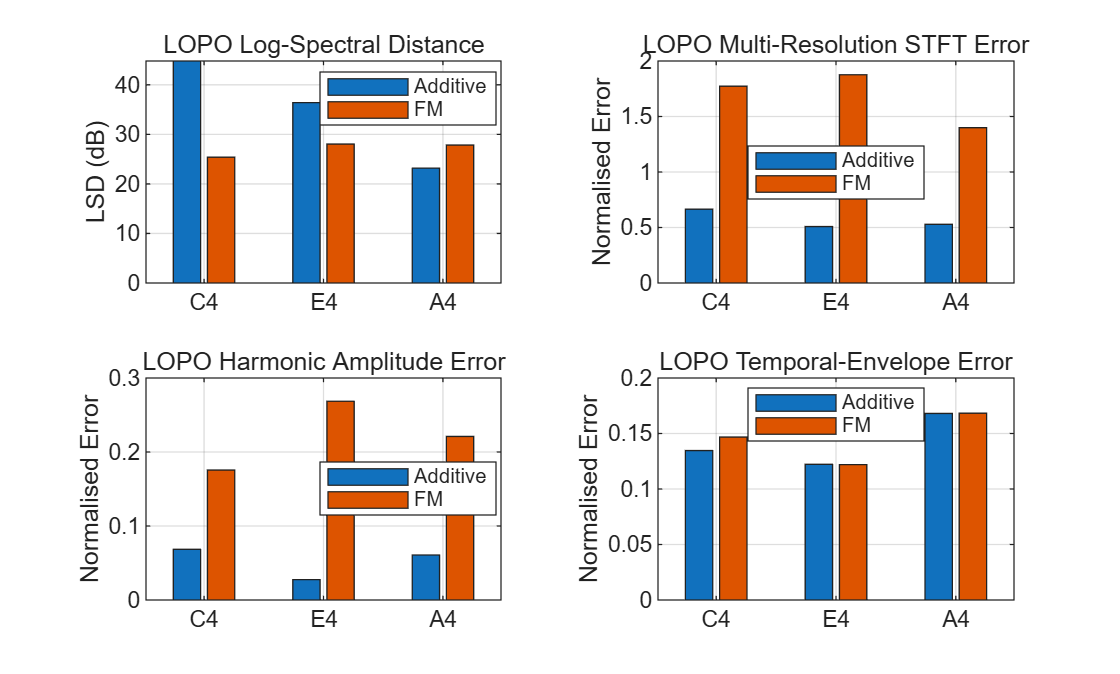



%% LOPO Quantitative Comparison Figure

figure;

tiledlayout(2,2);


% ---------------------------------------------------------
% LSD
% ---------------------------------------------------------

nexttile;

bar([ ...
    lopoAdditiveLSD, ...
    lopoFMLSD]);

title('LOPO Log-Spectral Distance');

ylabel('LSD (dB)');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Additive', ...
    'FM', ...
    'Location', ...
    'best');

grid on;


% ---------------------------------------------------------
% MR-STFT
% ---------------------------------------------------------

nexttile;

bar([ ...
    lopoAdditiveMRMean, ...
    lopoFMMRMean]);

title('LOPO Multi-Resolution STFT Error');

ylabel('Normalised Error');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Additive', ...
    'FM', ...
    'Location', ...
    'best');

grid on;


% ---------------------------------------------------------
% Harmonic Error
% ---------------------------------------------------------

nexttile;

bar([ ...
    lopoAdditiveHarmonicError, ...
    lopoFMHarmonicError]);

title('LOPO Harmonic Amplitude Error');

ylabel('Normalised Error');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Additive', ...
    'FM', ...
    'Location', ...
    'best');

grid on;


% ---------------------------------------------------------
% Envelope Error
% ---------------------------------------------------------

nexttile;

bar([ ...
    lopoAdditiveEnvelopeError, ...
    lopoFMEnvelopeError]);

title('LOPO Temporal-Envelope Error');

ylabel('Normalised Error');

xticks(1:numNotes);
xticklabels(notes);

legend( ...
    'Additive', ...
    'FM', ...
    'Location', ...
    'best');

grid on;


%% Save LOPO Evaluation Results

csvFile = fullfile( ...
    resultsFolder, ...
    'LOPO_Quantitative_Evaluation.csv');

writetable( ...
    LOPOEvaluationTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'LOPO_Quantitative_Mean_Results.csv');

writetable( ...
    LOPOMeanTable, ...
    meanCsvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'LOPO_Quantitative_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### Independent Reconstruction vs LOPO Transfer


% ---------------------------------------------------------
% Mean independent reconstruction results
% ---------------------------------------------------------

independentAdditiveLSD = ...
    mean(additiveLSD);

independentFMLSD = ...
    mean(fmLSD);

independentAdditiveMRSTFT = ...
    mean(additiveMRMean);

independentFMMRSTFT = ...
    mean(fmMRMean);

independentAdditiveHarmonic = ...
    mean(additiveHarmonicError);

independentFMHarmonic = ...
    mean(fmHarmonicError);

independentAdditiveEnvelope = ...
    mean(additiveEnvelopeError);

independentFMEnvelope = ...
    mean(fmEnvelopeError);


% ---------------------------------------------------------
% Mean LOPO transfer results
% ---------------------------------------------------------

transferAdditiveLSD = ...
    mean(lopoAdditiveLSD);

transferFMLSD = ...
    mean(lopoFMLSD);

transferAdditiveMRSTFT = ...
    mean(lopoAdditiveMRMean);

transferFMMRSTFT = ...
    mean(lopoFMMRMean);

transferAdditiveHarmonic = ...
    mean(lopoAdditiveHarmonicError);

transferFMHarmonic = ...
    mean(lopoFMHarmonicError);

transferAdditiveEnvelope = ...
    mean(lopoAdditiveEnvelopeError);

transferFMEnvelope = ...
    mean(lopoFMEnvelopeError);


%% Mean Comparison Table

Metric = {
    'LSD_dB'
    'MRSTFT_Error'
    'Harmonic_Error'
    'Envelope_Error'
};

Independent_Additive = [
    independentAdditiveLSD
    independentAdditiveMRSTFT
    independentAdditiveHarmonic
    independentAdditiveEnvelope
];

LOPO_Additive = [
    transferAdditiveLSD
    transferAdditiveMRSTFT
    transferAdditiveHarmonic
    transferAdditiveEnvelope
];

Independent_FM = [
    independentFMLSD
    independentFMMRSTFT
    independentFMHarmonic
    independentFMEnvelope
];

LOPO_FM = [
    transferFMLSD
    transferFMMRSTFT
    transferFMHarmonic
    transferFMEnvelope
];


IndependentVsLOPOTable = table( ...
    Metric, ...
    Independent_Additive, ...
    LOPO_Additive, ...
    Independent_FM, ...
    LOPO_FM);

IndependentVsLOPOTable

IndependentVsLOPOTable = 4×5 table
          Metric          Independent_Additive    LOPO_Additive    Independent_FM    LOPO_FM
    __________________    ____________________    _____________    ______________    _______

    {'LSD_dB'        }            35.147              34.802           24.595          27.09
    {'MRSTFT_Error'  }           0.17183             0.56757           1.6511         1.6828
    {'Harmonic_Error'}          0.018931            0.052275          0.25903        0.22175
    {'Envelope_Error'}          0.020146             0.14165          0.01317        0.14568

	使用 Copilot 获取洞察


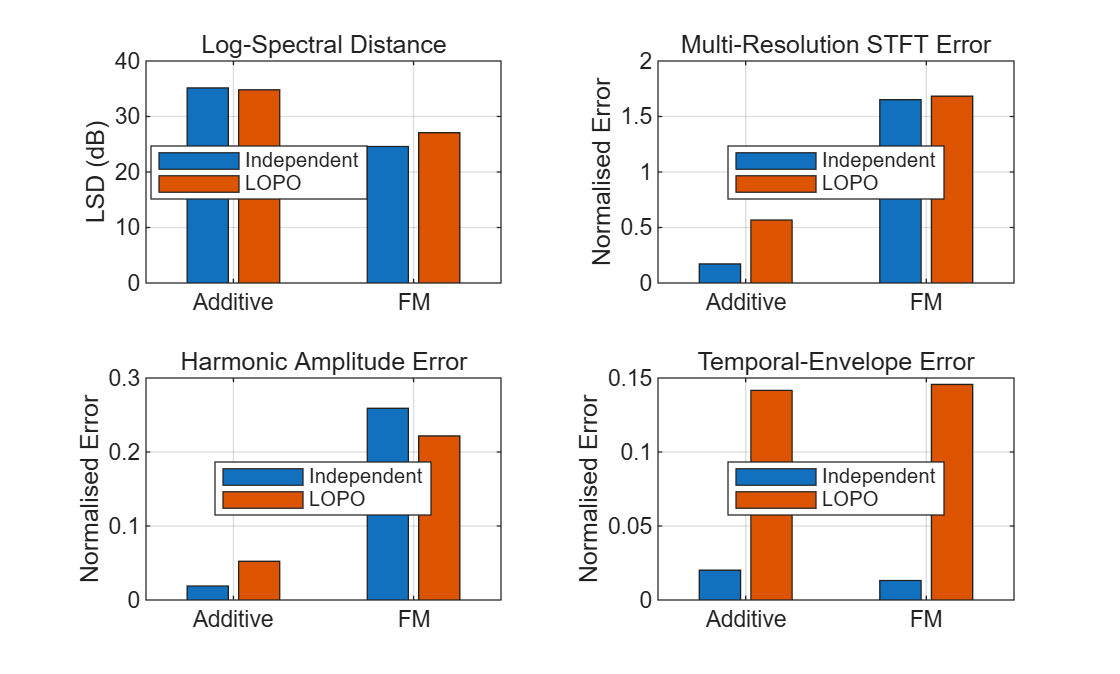



%% Independent vs LOPO Comparison Figure

figure;

tiledlayout(2,2);


% ---------------------------------------------------------
% LSD
% ---------------------------------------------------------

nexttile;

bar([
    independentAdditiveLSD, transferAdditiveLSD
    independentFMLSD, transferFMLSD
]);

xticklabels({
    'Additive'
    'FM'
});

ylabel('LSD (dB)');

title('Log-Spectral Distance');

legend( ...
    'Independent', ...
    'LOPO', ...
    'Location', ...
    'best');

grid on;


% ---------------------------------------------------------
% Multi-Resolution STFT
% ---------------------------------------------------------

nexttile;

bar([
    independentAdditiveMRSTFT, transferAdditiveMRSTFT
    independentFMMRSTFT, transferFMMRSTFT
]);

xticklabels({
    'Additive'
    'FM'
});

ylabel('Normalised Error');

title('Multi-Resolution STFT Error');

legend( ...
    'Independent', ...
    'LOPO', ...
    'Location', ...
    'best');

grid on;


% ---------------------------------------------------------
% Harmonic Amplitude Error
% ---------------------------------------------------------

nexttile;

bar([
    independentAdditiveHarmonic, transferAdditiveHarmonic
    independentFMHarmonic, transferFMHarmonic
]);

xticklabels({
    'Additive'
    'FM'
});

ylabel('Normalised Error');

title('Harmonic Amplitude Error');

legend( ...
    'Independent', ...
    'LOPO', ...
    'Location', ...
    'best');

grid on;


% ---------------------------------------------------------
% Temporal-Envelope Error
% ---------------------------------------------------------

nexttile;

bar([
    independentAdditiveEnvelope, transferAdditiveEnvelope
    independentFMEnvelope, transferFMEnvelope
]);

xticklabels({
    'Additive'
    'FM'
});

ylabel('Normalised Error');

title('Temporal-Envelope Error');

legend( ...
    'Independent', ...
    'LOPO', ...
    'Location', ...
    'best');

grid on;


%% Save Results

csvFile = fullfile( ...
    resultsFolder, ...
    'Independent_vs_LOPO_Mean_Comparison.csv');

writetable( ...
    IndependentVsLOPOTable, ...
    csvFile);


figureFile = fullfile( ...
    resultsFolder, ...
    'Independent_vs_LOPO_Comparison.png');

exportgraphics( ...
    gcf, ...
    figureFile, ...
    'Resolution', ...
    300);

### LOPO Residual Spectral Analysis


% ---------------------------------------------------------
% Settings
% ---------------------------------------------------------

residualWindowLength = 2048;
residualOverlapLength = 1536;
residualNfft = 4096;

maxResidualFrequency = 5000;

highFrequencyBoundary = 2000;

numNotes = length(notes);


% ---------------------------------------------------------
% Storage
% ---------------------------------------------------------

additiveTotalMissing = zeros(numNotes,1);
fmTotalMissing = zeros(numNotes,1);

additiveHighFreqMissing = zeros(numNotes,1);
fmHighFreqMissing = zeros(numNotes,1);

additiveResidualDB = cell(numNotes,1);
fmResidualDB = cell(numNotes,1);

residualFrequencyAxis = cell(numNotes,1);


%% Residual Spectral Analysis

for i = 1:numNotes

    % -----------------------------------------------------
    % Load audio
    % -----------------------------------------------------

    [xRef, fsRef] = ...
        audioread(referenceFiles{i});

    [xAdd, fsAdd] = ...
        audioread(lopoAdditiveEvalFiles{i});

    [xFM, fsFM] = ...
        audioread(lopoFMEvalFiles{i});


    % -----------------------------------------------------
    % Convert to mono
    % -----------------------------------------------------

    if size(xRef,2) == 2
        xRef = mean(xRef,2);
    end

    if size(xAdd,2) == 2
        xAdd = mean(xAdd,2);
    end

    if size(xFM,2) == 2
        xFM = mean(xFM,2);
    end


    % -----------------------------------------------------
    % Match sampling rates
    % -----------------------------------------------------

    if fsAdd ~= fsRef
        xAdd = resample(xAdd, fsRef, fsAdd);
    end

    if fsFM ~= fsRef
        xFM = resample(xFM, fsRef, fsFM);
    end

    fs = fsRef;


    % -----------------------------------------------------
    % Match signal lengths
    % -----------------------------------------------------

    minLength = min( ...
        [length(xRef), ...
         length(xAdd), ...
         length(xFM)]);

    xRef = xRef(1:minLength);
    xAdd = xAdd(1:minLength);
    xFM  = xFM(1:minLength);


    % -----------------------------------------------------
    % Normalise waveforms
    % -----------------------------------------------------

    if max(abs(xRef)) > 0
        xRef = xRef / max(abs(xRef));
    end

    if max(abs(xAdd)) > 0
        xAdd = xAdd / max(abs(xAdd));
    end

    if max(abs(xFM)) > 0
        xFM = xFM / max(abs(xFM));
    end


    % -----------------------------------------------------
    % STFT
    % -----------------------------------------------------

    [Sref, F, ~] = spectrogram( ...
        xRef, ...
        hann(residualWindowLength), ...
        residualOverlapLength, ...
        residualNfft, ...
        fs);

    [Sadd, ~, ~] = spectrogram( ...
        xAdd, ...
        hann(residualWindowLength), ...
        residualOverlapLength, ...
        residualNfft, ...
        fs);

    [Sfm, ~, ~] = spectrogram( ...
        xFM, ...
        hann(residualWindowLength), ...
        residualOverlapLength, ...
        residualNfft, ...
        fs);


    % -----------------------------------------------------
    % Restrict to 0-5 kHz
    % -----------------------------------------------------

    freqMask = ...
        F <= maxResidualFrequency;

    F = F(freqMask);

    refMagnitude = ...
        mean(abs(Sref(freqMask,:)),2);

    addMagnitude = ...
        mean(abs(Sadd(freqMask,:)),2);

    fmMagnitude = ...
        mean(abs(Sfm(freqMask,:)),2);


    % -----------------------------------------------------
    % Convert to normalised spectral distributions
    % -----------------------------------------------------

    refDistribution = ...
        refMagnitude / ...
        (sum(refMagnitude) + 1e-12);

    addDistribution = ...
        addMagnitude / ...
        (sum(addMagnitude) + 1e-12);

    fmDistribution = ...
        fmMagnitude / ...
        (sum(fmMagnitude) + 1e-12);


    % -----------------------------------------------------
    % Linear residual
    %
    % Positive:
    % reference contains more spectral energy
    %
    % Negative:
    % synthesis contains excess spectral energy
    % -----------------------------------------------------

    addResidual = ...
        refDistribution - ...
        addDistribution;

    fmResidual = ...
        refDistribution - ...
        fmDistribution;


    % -----------------------------------------------------
    % Total missing spectral energy
    % -----------------------------------------------------

    additiveTotalMissing(i) = ...
        sum(max(addResidual,0));

    fmTotalMissing(i) = ...
        sum(max(fmResidual,0));


    % -----------------------------------------------------
    % Missing high-frequency energy
    %
    % 2-5 kHz region
    % -----------------------------------------------------

    highFreqMask = ...
        F >= highFrequencyBoundary & ...
        F <= maxResidualFrequency;


    additiveHighFreqMissing(i) = ...
        sum( ...
        max( ...
        addResidual(highFreqMask), ...
        0));


    fmHighFreqMissing(i) = ...
        sum( ...
        max( ...
        fmResidual(highFreqMask), ...
        0));


    % -----------------------------------------------------
    % Residual in dB for visualisation
    % -----------------------------------------------------

    epsilon = 1e-10;


    addResidualDBCurrent = ...
        20 * log10( ...
        refDistribution + epsilon) - ...
        20 * log10( ...
        addDistribution + epsilon);


    fmResidualDBCurrent = ...
        20 * log10( ...
        refDistribution + epsilon) - ...
        20 * log10( ...
        fmDistribution + epsilon);


    % Smooth only for visualisation
    addResidualDBCurrent = ...
        movmean( ...
        addResidualDBCurrent, ...
        9);

    fmResidualDBCurrent = ...
        movmean( ...
        fmResidualDBCurrent, ...
        9);


    additiveResidualDB{i} = ...
        addResidualDBCurrent;

    fmResidualDB{i} = ...
        fmResidualDBCurrent;

    residualFrequencyAxis{i} = F;

end


%% Residual Results Table

ResidualTable = table( ...
    notes', ...
    additiveTotalMissing, ...
    fmTotalMissing, ...
    additiveHighFreqMissing, ...
    fmHighFreqMissing, ...
    'VariableNames', ...
    { ...
    'Note', ...
    'Additive_Total_Missing', ...
    'FM_Total_Missing', ...
    'Additive_HF_Missing', ...
    'FM_HF_Missing' ...
    });

ResidualTable

ResidualTable = 3×5 table
     Note     Additive_Total_Missing    FM_Total_Missing    Additive_HF_Missing    FM_HF_Missing
    ______    ______________________    ________________    ___________________    _____________

    {'C4'}           0.31384                0.81372               0.18846             0.13005   
    {'E4'}           0.16156                0.90786              0.069805             0.08168   
    {'A4'}            0.2452                0.85768              0.050983            0.098493   

	使用 Copilot 获取洞察




%% Mean Residual Results

ResidualMeanTable = table( ...
    mean(additiveTotalMissing), ...
    mean(fmTotalMissing), ...
    mean(additiveHighFreqMissing), ...
    mean(fmHighFreqMissing), ...
    'VariableNames', ...
    { ...
    'Mean_Additive_Total_Missing', ...
    'Mean_FM_Total_Missing', ...
    'Mean_Additive_HF_Missing', ...
    'Mean_FM_HF_Missing' ...
    });

ResidualMeanTable

ResidualMeanTable = 1×4 table
    Mean_Additive_Total_Missing    Mean_FM_Total_Missing    Mean_Additive_HF_Missing    Mean_FM_HF_Missing
    ___________________________    _____________________    ________________________    __________________

              0.2402                      0.85975                   0.10308                  0.10341      

	使用 Copilot 获取洞察


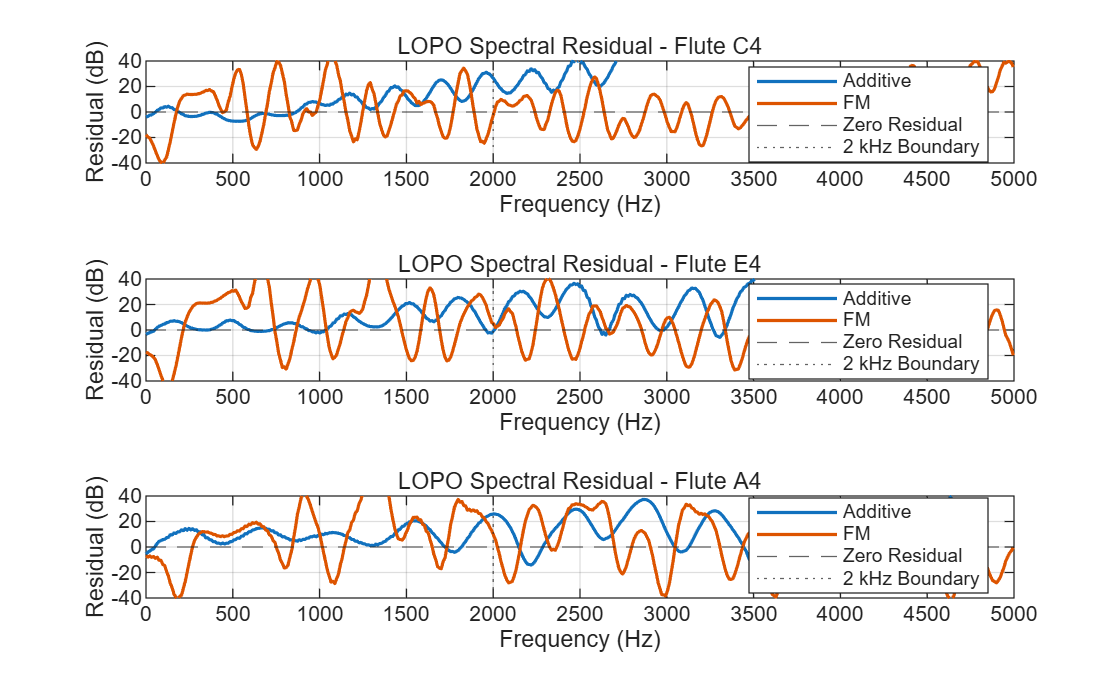



%% Residual Spectral Structure Figure

figure;

tiledlayout(3,1);


for i = 1:numNotes

    nexttile;

    plot( ...
        residualFrequencyAxis{i}, ...
        additiveResidualDB{i}, ...
        'LineWidth', ...
        1.2);

    hold on;

    plot( ...
        residualFrequencyAxis{i}, ...
        fmResidualDB{i}, ...
        'LineWidth', ...
        1.2);

    yline( ...
        0, ...
        '--');

    xline( ...
        highFrequencyBoundary, ...
        ':');

    xlim([0 maxResidualFrequency]);

    ylim([-40 40]);

    xlabel('Frequency (Hz)');

    ylabel('Residual (dB)');

    title( ...
        ['LOPO Spectral Residual - Flute ', ...
         notes{i}]);

    legend( ...
        'Additive', ...
        'FM', ...
        'Zero Residual', ...
        '2 kHz Boundary', ...
        'Location', ...
        'best');

    grid on;

end

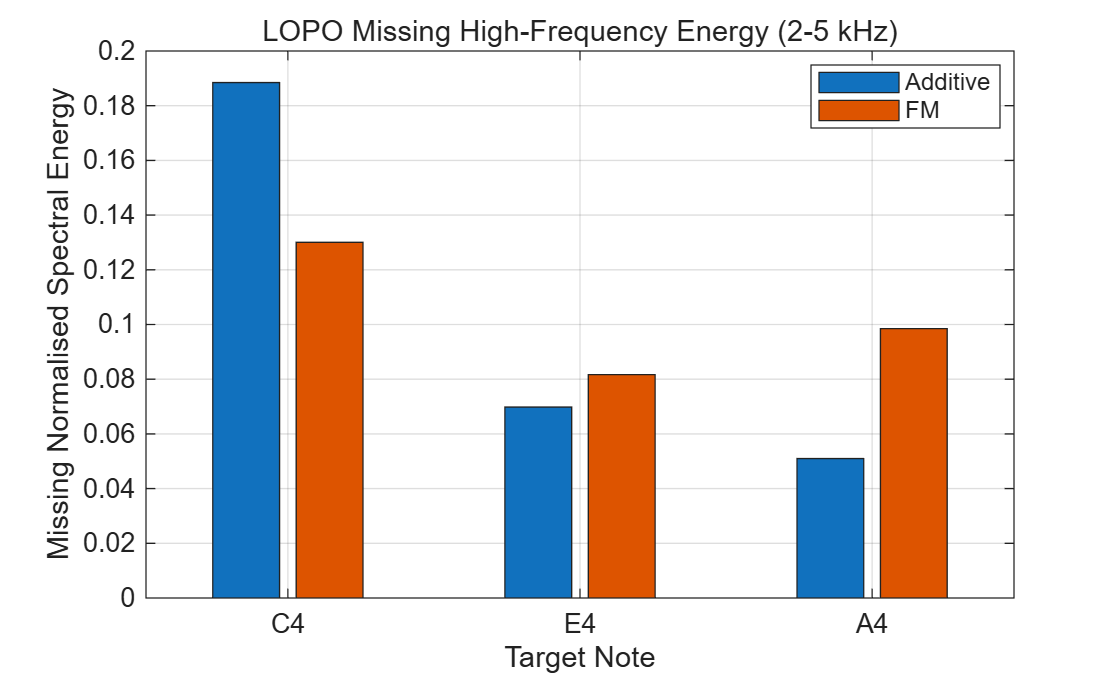



%% Missing High-Frequency Energy Figure

figure;

bar([ ...
    additiveHighFreqMissing, ...
    fmHighFreqMissing]);

xlabel('Target Note');

ylabel('Missing Normalised Spectral Energy');

title( ...
    'LOPO Missing High-Frequency Energy (2-5 kHz)');

xticks(1:numNotes);

xticklabels(notes);

legend( ...
    'Additive', ...
    'FM', ...
    'Location', ...
    'best');

grid on;

Save Residual Results


% ---------------------------------------------------------
% Save result tables
% ---------------------------------------------------------

csvFile = fullfile( ...
    resultsFolder, ...
    'LOPO_Residual_Spectral_Results.csv');

writetable( ...
    ResidualTable, ...
    csvFile);


meanCsvFile = fullfile( ...
    resultsFolder, ...
    'LOPO_Residual_Spectral_Mean_Results.csv');

writetable( ...
    ResidualMeanTable, ...
    meanCsvFile);


%% Residual Spectral Structure Figure

residualFigure = figure;

tiledlayout(3,1);


for i = 1:numNotes

    nexttile;

    plot( ...
        residualFrequencyAxis{i}, ...
        additiveResidualDB{i}, ...
        'LineWidth', ...
        1.2);

    hold on;

    plot( ...
        residualFrequencyAxis{i}, ...
        fmResidualDB{i}, ...
        'LineWidth', ...
        1.2);

    yline( ...
        0, ...
        '--');

    xline( ...
        highFrequencyBoundary, ...
        ':');

    xlim([0 maxResidualFrequency]);

    ylim([-40 40]);

    xlabel('Frequency (Hz)');

    ylabel('Residual (dB)');

    title( ...
        ['LOPO Spectral Residual - Flute ', ...
         notes{i}]);

    legend( ...
        'Additive', ...
        'FM', ...
        'Zero Residual', ...
        '2 kHz Boundary', ...
        'Location', ...
        'best');

    grid on;

end


%% Save Residual Structure Figure

exportgraphics( ...
    residualFigure, ...
    fullfile( ...
    resultsFolder, ...
    'LOPO_Residual_Spectral_Structure.png'), ...
    'Resolution', ...
    300);



%% Missing High-Frequency Energy Figure

hfFigure = figure;

bar([ ...
    additiveHighFreqMissing, ...
    fmHighFreqMissing]);

xlabel('Target Note');

ylabel('Missing Normalised Spectral Energy');

title( ...
    'LOPO Missing High-Frequency Energy (2-5 kHz)');

xticks(1:numNotes);

xticklabels(notes);

legend( ...
    'Additive', ...
    'FM', ...
    'Location', ...
    'best');

grid on;


%% Save High-Frequency Figure

exportgraphics( ...
    hfFigure, ...
    fullfile( ...
    resultsFolder, ...
    'LOPO_High_Frequency_Missing_Energy.png'), ...
    'Resolution', ...
    300);